# Neural and acoustic distance: congruence of networks?

Can we find any correlates between differences of vocal gestures and differences of neural activity?

There are undesirable covariate in the data: systematic other behaviors and corresponding neural response (interaction at the mesh) that correlate only with a certain type of call that by definition have acoustic features themselves really different from other type of call. Because we cannot reliably annotate these other behaviors, we cannot regress them out. So we need to focus on only one call type and see how these are covarying with neural activity.

Linear models of the type Rate ~ Acoustic feature (Gaussian, Gamma, Poisson) have several issues though:

1- We need to find a right time scale to input to the model: small binning increase the noise, but large time scale might crush the information and in particular eliminate any temporal information.

2- to over come the noise we need a large number of repetition, which we currently don't have in our dataset (need to plot here the cumulative time (duration) of vocalizations, which is the true exploitable value as compared to # calls).

Let's do a dimensionality reduction on the neural response and explore neural tuning in that reduced space.

One first idea for exploring neural tuning, to see if there is anything:

The idea here is to represent neural activity of single units into the same basis set of the PCA, then for each unit calculate the distance between pattern of activity around each vocalization and compare that with the distance of vocalizations in the acoustic space

## Representing neural responses in basis set of PCA

% Load the list of cells that show promising vocalizer patterns as
% demonstrated by the PCA/GLMM approach on average KDE over Trill and
% non-Trill calls (see explore_populationSU.mlx)
Path2AllData = '/Volumes/JulieE8T/LMCResults';
load(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'ListCellsListPCAComponent','MahalDistanceL2','LCells', 'GoodCellIndices', 'ListCells', 'OperantVocalizer', 'BaorTr_0ind')
%load(fullfile(Path2AllData,'explore_populationSU_data.mat'))
% According the above mentioned notebook, 75% of these cells have a time
% resolution obtained with Coherence on Amplitude that is higher than
% 5.9ms. Let's take 5ms as the width of our Gaussian on all cells and all
% spike patterns around vocal production
TR = 10; %in ms
% also according to the above notebook, the smallest Optimal delay between
% neural response and amplitude of the vocaliztaion for optimal values of
% coherence in -98ms, so let's take neural activity only 100ms before
% vocalizations onset
Delay = 100; %in ms
% cells that have enough vocalizer Trills (>8)


% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% select cells that are from Listner of either Trills or non-trills or both during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGL = ListCellsG(logical((~OperantVocalizer).*BaorTr_0ind));
% These are cells with the out of the chart values for components that
% discriminate Listener from vocalizer
%ListCellsList = ListCellsListPCAComponent(~isnan(MahalDistanceL2(logical(LCells(:,1)),1)));
% These are the cells ordered by decreasing value of Mahaldistance for
% Trills
% MaxMahalDistanceL2 = max(MahalDistanceL2,[],2);
[~,OrdMax] = sort(MahalDistanceL2(:,1), 'descend');
LastNan = find(isnan(MahalDistanceL2(OrdMax,1)), 1,'last');
ListCellsList = ListCellsGL(OrdMax(LastNan+(1:100)));
NC = 62;

% Obtain a large matrix of all single Trill neural activity from all
% cells NOTE:!!!! Would make sense to sample equally the cells (same number
% of vocalization for each cell, such as not to bias the basis set towards
% some particular cells? No in fact we just want the data to all be well
% represented
RateTrills = cell(1,NC);
MeanRateTrills = cell(1,NC);
StimDuraMax = nan(NC,1); % gather the maximum duration of vocalization for each cell. The final matrix will be  hard cut at max(StimDuraMin)+100ms
NStims = nan(NC,1);
ListCellsListNew = cell(NC,1);
cc=0;
ii=0;
while cc<62
    ii=ii+1;
    % load the cell
    fprintf(1,'Cell %d/%d\n', ii, 100)
    Cell = load(ListCellsList{ii}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        continue
    end
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* ~contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        if length(IndVoc)<10 % focus on cell that have at least 10 Trills calls
            fprintf(1,'*** Not enough calls (n=%d)!! ****\n',length(IndVoc))
            continue
        end
        NStims_local = length(IndVoc);
        StimDura = nan(NStims_local,1);
        for sss=1:NStims_local
            StimDura(sss) = round(length(Cell.BioSound{IndVoc(sss),2}.sound) ./(Cell.BioSound{IndVoc(sss),2}.samprate)*10^3);
        end
        if any(abs(StimDura - Cell.Duration(IndVoc))>1)
            fprintf(1,'*** Problem with Cell: duration inconcistency!! ****\n')
            keyboard
            fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
            return
        end
        

    % calculate the Time varying Gaussian filtered spike rate for each
    % vocalization and also the average spike rate during the vocalization
    % starting -100ms before stim on set and stopping at stim offset
    % neural response is a vector that compile for each stim all spike counts starting
    % at -100ms (Delay) before stim onset and stop at 2000ms after
    % stim onset with a time resolution TR
    [YPerStim, YPerStimt, MeanRateTrills_local] = get_y(Cell.SpikesArrivalTimes_Behav(IndVoc), Cell.Duration(IndVoc),[-Delay 2000],TR);
    if sum(sum(YPerStim))==0
        fprintf(1,'*** Null spike rate!! ****\n')
        continue
    end
    cc=cc+1;
    ListCellsListNew{cc} = ListCellsList{ii};
    NStims(cc) = NStims_local;
    StimDuraMax(cc) = max(StimDura);
    RateTrills{cc} = YPerStim';
    MeanRateTrills{cc} = MeanRateTrills_local;
end

Cell 1/100
Cell 2/100
Cell 3/100
Cell 4/100
Cell 5/100
Cell 6/100
Cell 7/100
Cell 8/100
Cell 9/100
Cell 10/100
Cell 11/100
Cell 12/100
Cell 13/100
Cell 14/100
Cell 15/100
Cell 16/100
Cell 17/100
Cell 18/100
Cell 19/100
Cell 20/100
Cell 21/100
Cell 22/100
Cell 23/100
Cell 24/100
Cell 25/100
Cell 26/100
Cell 27/100
Cell 28/100
Cell 29/100
Cell 30/100
Cell 31/100
Cell 32/100
Cell 33/100
Cell 34/100
Cell 35/100
Cell 36/100
Cell 37/100
Cell 38/100
Cell 39/100
Cell 40/100
Cell 41/100
Cell 42/100
Cell 43/100
Cell 44/100
Cell 45/100
Cell 46/100
Cell 47/100
Cell 48/100
Cell 49/100
Cell 50/100
Cell 51/100
Cell 52/100
Cell 53/100
Cell 54/100
Cell 55/100
Cell 56/100
Cell 57/100
Cell 58/100
Cell 59/100
Cell 60/100
Cell 61/100
Cell 62/100


ListCellsList = ListCellsListNew;
save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data.mat'), 'RateTrills', 'MeanRateTrills','NStims','StimDuraMax', 'ListCellsList')

RateTrills_mat = [RateTrills{:}]';
% cut the matrix at mean(Max duration of vocalization) + Delay/2
StimDuraOpt = round(mean(StimDuraMax)/10)*10;
RateTrills_mat = RateTrills_mat(:, 1:StimDuraOpt+1.5*Delay);
% substract the time varying mean
RateTrills_centered = RateTrills_mat - mean(RateTrills_mat);
[PC,Score,~, ~, VarExpl,~] = pca(RateTrills_mat);

% Run a PCA per cell
PC_per_cell = cell(NC,1);
Score_per_cell = cell(NC,1);
VarExpl_per_cell = cell(NC,1);
RateTrills_mat_per_cell = cell(NC,1);
NPC_per_cell = nan(NC,1);
for cc=1:NC
    RateTrills_mat_per_cell{cc} = RateTrills{cc}(1:StimDuraOpt+1.5*Delay,:)';
    [PC_per_cell{cc},Score_per_cell{cc},~, ~, VarExpl_per_cell{cc},~] = pca(RateTrills_mat_per_cell{cc});
    NPC_per_cell(cc)=find(cumsum(VarExpl_per_cell{cc})>90,1);
end

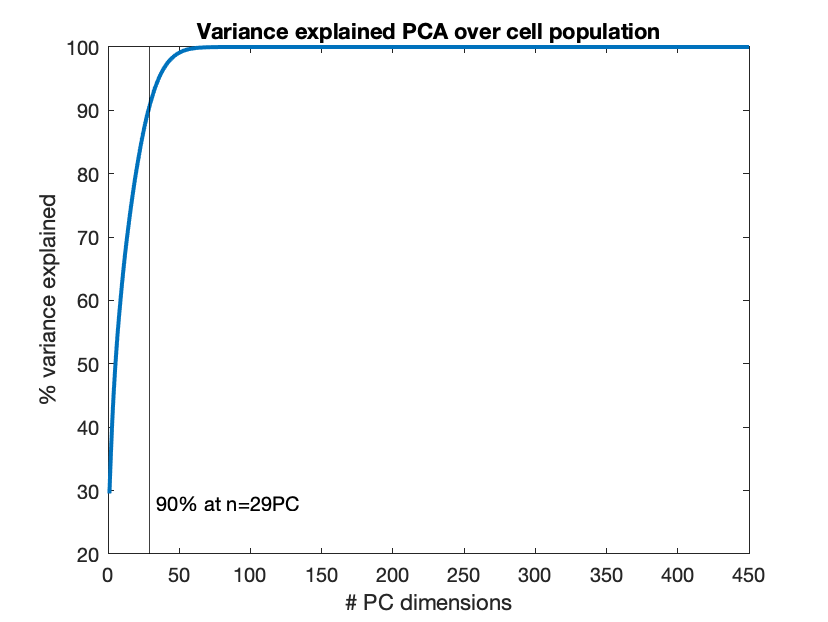

% Plot the variance explained
figure
plot(cumsum(VarExpl), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl)>90,1), '-k',sprintf('90%% at n=%dPC', find(cumsum(VarExpl)>90,1)))
hold off
title('Variance explained PCA over cell population')

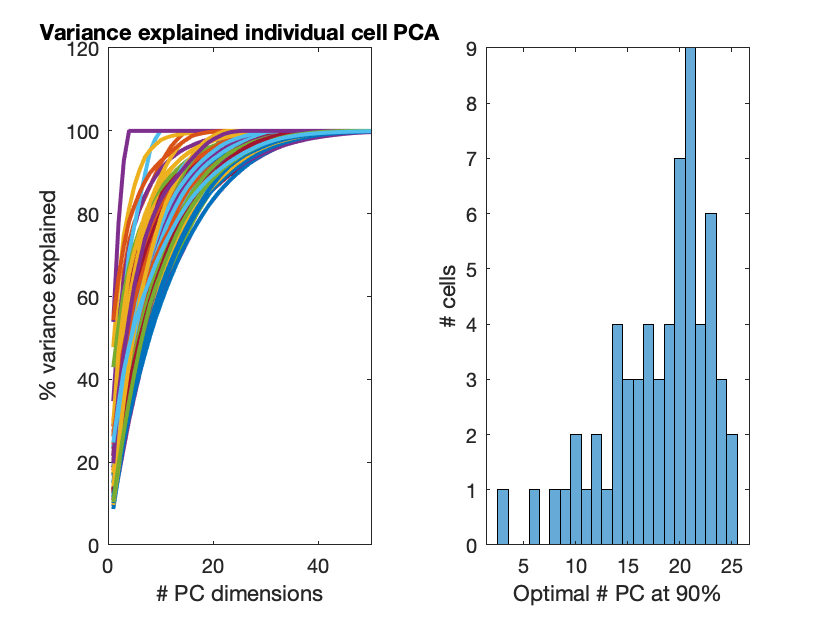

% Plot the variance explained for individual cells PCA
t=tiledlayout(1,2);
CumsumVE = nan(NC,20);
nexttile
for cc=1:NC
    plot(cumsum(VarExpl_per_cell{cc}), 'LineWidth',2)
    xlabel('# PC dimensions')
    ylabel('% variance explained')
    hold on
    VarMax = min(length(VarExpl_per_cell{cc}),20);
    CumsumVE(cc,1:VarMax) = cumsum(VarExpl_per_cell{cc}(1:VarMax));
end
xlim([0 50])
title('Variance explained individual cell PCA')
hold off
nexttile
histogram(NPC_per_cell)
xlabel('Optimal # PC at 90%')
ylabel('# cells')

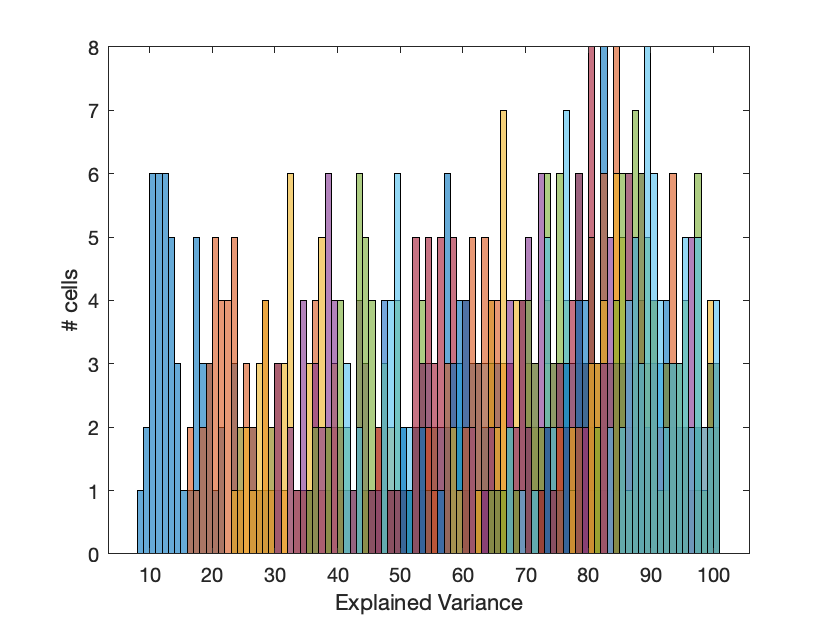


figure
for pp=1:20
    histogram(CumsumVE(:,pp),'BinWidth',1, 'DisplayName', sprintf('%d',pp))
    hold on
end
xlabel('Explained Variance')
ylabel('# cells')
hold off

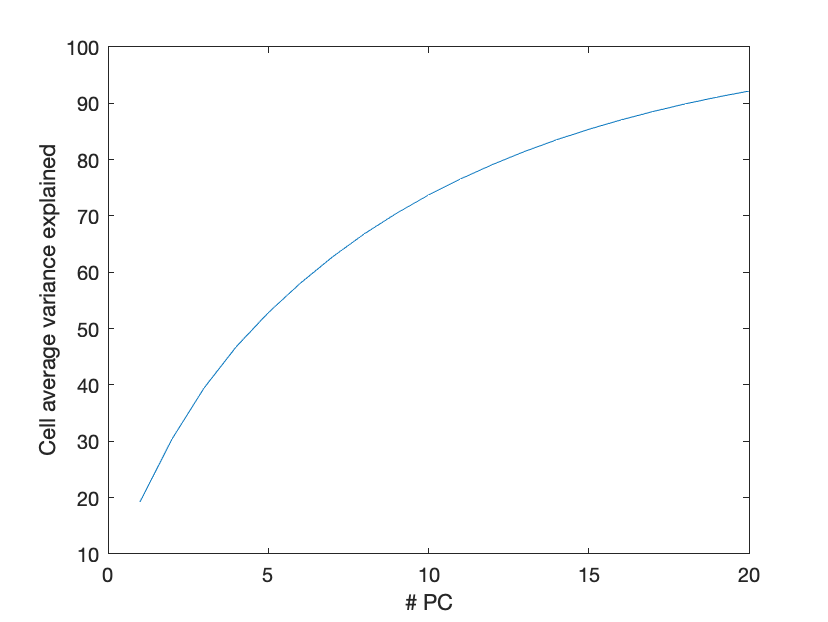


figure
plot(nanmean(CumsumVE))
xlabel('# PC')
ylabel('Cell average variance explained')

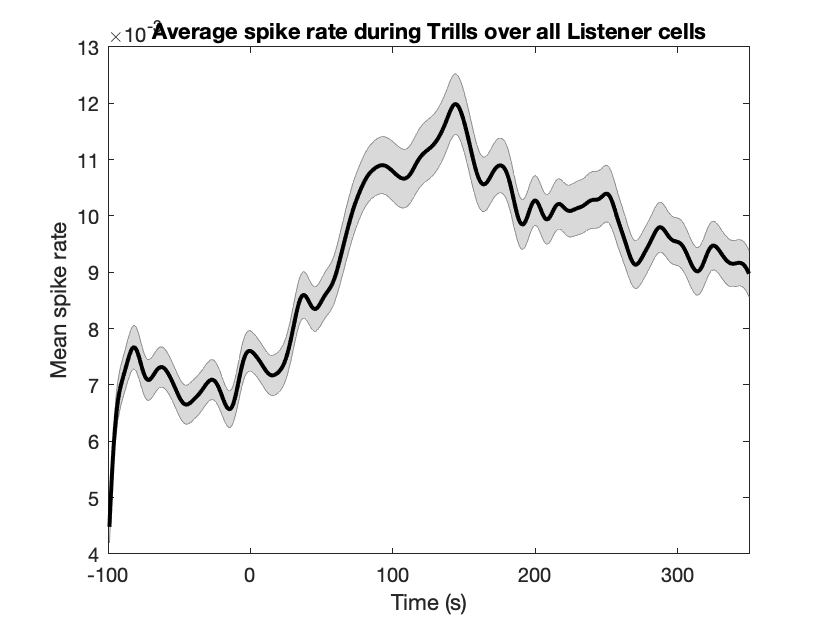

% Plot the average time varying rate
figure
shadedErrorBar([],mean(RateTrills_mat), std(RateTrills_mat)*(size(RateTrills_mat,1))^-0.5, {'k-','LineWidth',2});ylabel('Mean spike rate');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt+Delay/2));title('Average spike rate during Trills over all Listener cells')
hold off

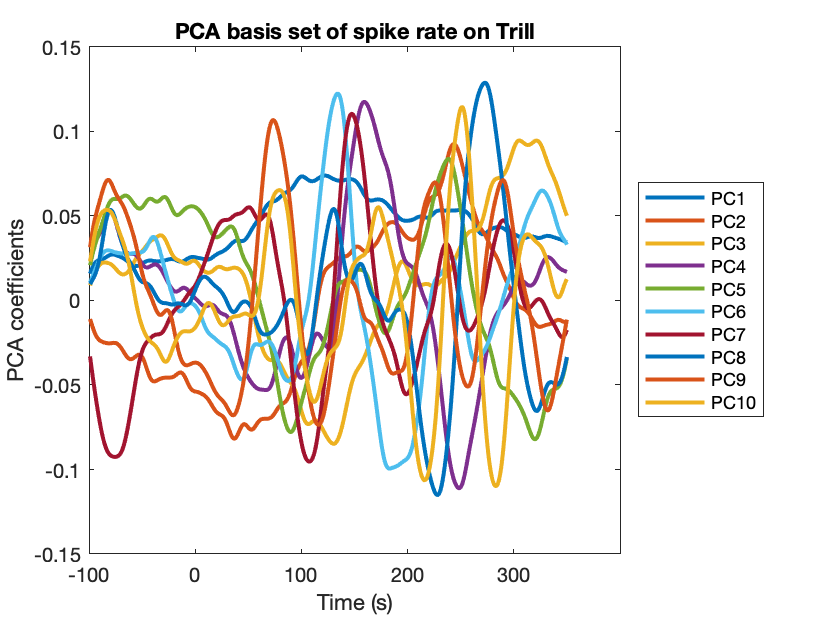


% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt+Delay/2));title('PCA basis set of spike rate on Trill')
hold off

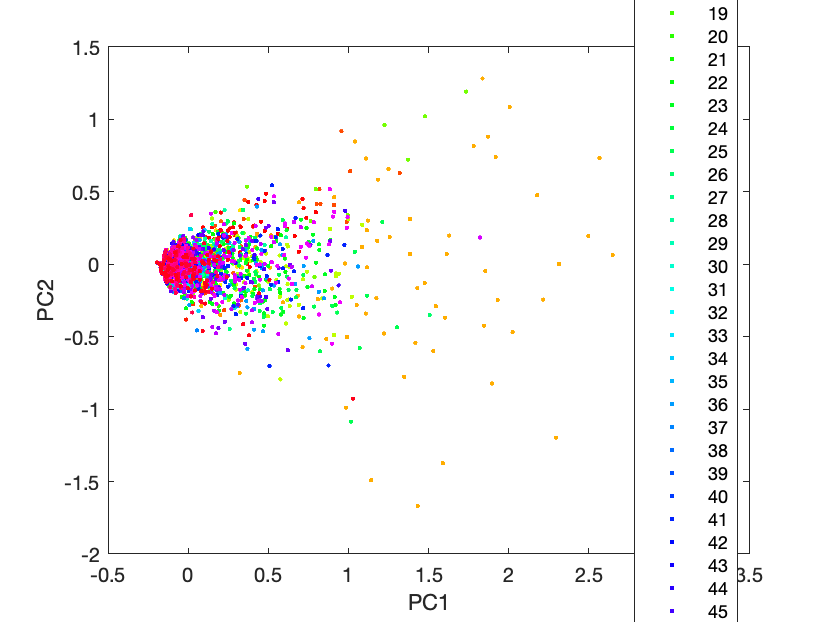

% plot all cells in the PC space
CellID = cell(1,NC);
for cc=1:NC
    CellID{cc} = cc.*ones(1,NStims(cc));
end
CellID = [CellID{:}]';
gscatter(Score(:,1), Score(:,2), CellID)
xlabel('PC1')
ylabel('PC2')

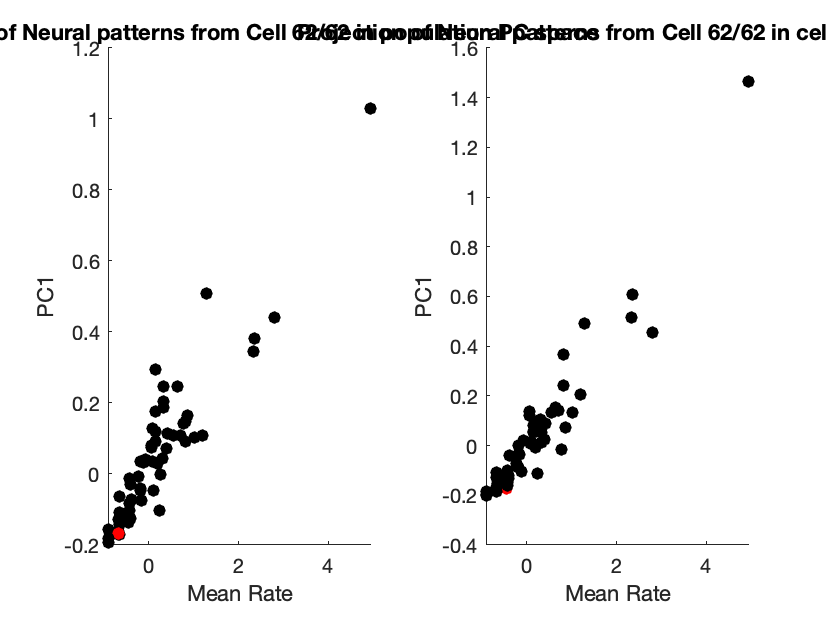

% Obtain the matrix of neural distance for each cell
% calculate for each cell the centroid of the cloud of responses and find
% the neural pattern (the instance) that is closer to the centroid. It will
% Obtain the matrix of neural distance for each cell
% calculate for each cell the centroid of the cloud of responses and find
% the neural pattern (the instance) that is closer to the centroid. It will
% be used as a reference point to calculate distance to other instances
NPC = find(cumsum(VarExpl)>90,1);
NeuralVectorDistance = cell(NC,3); % first column: PCA over all responses from all cells; second column: PCA per cell; third column: zscored time average rate;fourth column PCA per cell + zscore Rate
NeuralMatrixDistance = cell(NC,3);% first column: PCA over all responses from all cells; second column: PCA per cell; third column: zscored time average rate; fourth column PCA per cell + zscore Rate
for cc=1:NC
    % Using Cellpopulation PCA
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(cc)),1:min(NPC, floor(NStims(cc)/10)));
    % Calculate the centroid of the cloud of observations
    Centroid = mean(Score_local);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([Score_local; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc,1} = D(CentralInstance(1), 1:end-1);
    NeuralMatrixDistance{cc,1} = D(1:(end-1), 1:end-1);
    
    % Using individual cell PCA
    Score_local2 = Score_per_cell{cc}(:,1:min(NPC_per_cell(cc), floor(NStims(cc)/10)));
    % Calculate the centroid of the cloud of observations
    Centroid = mean(Score_local2);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([Score_local2; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance2 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc,2} = D(CentralInstance2(1), 1:end-1);
    NeuralMatrixDistance{cc,2} = D(1:(end-1), 1:end-1);

    % Using z-scored rate only
    % Calculate the centroid of the cloud of observations
    Centroid = mean(zscore(MeanRateTrills{cc}));
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([zscore(MeanRateTrills{cc}) ; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance3 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc,3} = D(CentralInstance3(1), 1:end-1);
    NeuralMatrixDistance{cc,3} = D(1:(end-1), 1:end-1);
    
    % Using individual cell PCA + zscoreRate
    Score_local3 = [Score_local2 zscore(MeanRateTrills{cc})];
    % Calculate the centroid of the cloud of observations
    Centroid = mean(Score_local3);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([Score_local3; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance4 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc,4} = D(CentralInstance4(1), 1:end-1);
    NeuralMatrixDistance{cc,4} = D(1:(end-1), 1:end-1);

    % plot
    Col = zeros(NStims(cc),3);
    Col(CentralInstance(1),:) = [1 0 0];
    tiledlayout(1,2)
    nexttile
    scatter(zscore(MeanRateTrills{cc}),Score_local(:,1),40,Col, 'filled')
    xlabel('Mean Rate')
    ylabel('PC1')
    title(sprintf('Projection of Neural patterns from Cell %d/%d in population PC space', cc, NC))
    nexttile
    Col = zeros(NStims(cc),3);
    Col(CentralInstance2(1),:) = [1 0 0];
    scatter(zscore(MeanRateTrills{cc}),Score_local2(:,1),40,Col, 'filled')
    xlabel('Mean Rate')
    ylabel('PC1')
    title(sprintf('Projection of Neural patterns from Cell %d/%d in cell PC space', cc, NC))
%     pause()
end

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data.mat'), 'NeuralMatrixDistance','NeuralVectorDistance','NPC','NPC_per_cell', 'Score', 'Score_per_cell','PC_per_cell', '-append')

## Representing Vocalizations in an acoustic basis set

Let's represent Trills iteratively by PCA on a given time varying acoustic feature, substracting the time varying mean acoustic feature

% Import Biosound library
py.importlib.import_module('soundsig')

ans =   Python module with properties:

           sound: [1×1 py.module]
    detect_peaks: [1×1 py.module]
          signal: [1×1 py.module]
        timefreq: [1×1 py.module]

    <module 'soundsig' from '/Users/elie/anaconda3/lib/python3.7/site-packages/soundsig/__init__.py'>



% Obtain a large matrix of all single Trill time varying pitch, amplitude, saliency etc...
Trills_fund = cell(1,NC);
Trills_sal = cell(1,NC);
Trills_amp = cell(1,NC);
Trills_specMean = cell(1,NC);
Trills_formDisp = cell(1,NC);
Trills_mps = cell(1,NC);
Trills_spectroPiezoto = cell(1,NC);
Trills_spectroPiezofo = cell(1,NC);
Trills_spectroPiezo = cell(1,NC);
Trills_spectroMicto = cell(1,NC);
Trills_spectroMicfo = cell(1,NC);
Trills_spectroMic = cell(1,NC);
SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:NC
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, NC)
    Cell = load(ListCellsList{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* ~contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        if length(IndVoc)<10 % focus on cell that have at least 10 Trills calls
            fprintf(1,'*** Not enough calls (n=%d)!! ****\n',length(IndVoc))
            continue
        end
    end
    
    % initialize the matrix of acoustic values with zeros
    Trills_fund{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_sal{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_amp{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_specMean{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_formDisp{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_mps{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezo{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezoto{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezofo{cc} = cell(1, length(IndVoc));
    Trills_spectroMic{cc} = cell(1, length(IndVoc));
    Trills_spectroMicto{cc} = cell(1, length(IndVoc));
    Trills_spectroMicfo{cc} = cell(1, length(IndVoc));

    
    % collect the Time varying smoothed acoustic features for each
    % vocalization
    for Nstim = 1:NStims(cc)
        StimDur = length(Cell.BioSound{IndVoc(Nstim),1}.amp);
        Trills_fund{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
        Trills_sal{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
        Trills_amp{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
        Trills_specMean{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
        F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
        F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
        Trills_formDisp{cc}(1:StimDur,Nstim) = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
        % Calculate the MPS and save it
        FS = Cell.BioSound{IndVoc(Nstim),1}.samprate;
        Y = zeros(max(StimDuraMax)*FS/10^3,1);
        Sound = Cell.BioSound{IndVoc(Nstim),1}.sound;
        Y(1:length(Sound)) = Sound;
        [MPS, Wf, Wt] = mps_calc(Y, FS);
        if Nstim>1
            if any(Trills_wf ~= Wf)
                return
            end
            if any(Trills_wt ~= Wt)
                return
            end
        end
        Trills_wt = Wt;
        Trills_wf = Wf;
        Trills_mps{cc}{Nstim}= reshape(MPS, numel(MPS),1);
        Trills_spectroPiezo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.spectro;
        Trills_spectroPiezoto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.to;
        Trills_spectroPiezofo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.fo;
        Trills_spectroMic{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.spectro;
        Trills_spectroMicto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.to;
        Trills_spectroMicfo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.fo;

    end
end

Cell 1/62
Cell 2/62
Cell 3/62
Cell 4/62
Cell 5/62
Cell 6/62
Cell 7/62
Cell 8/62
Cell 9/62
Cell 10/62
Cell 11/62
Cell 12/62
Cell 13/62
Cell 14/62
Cell 15/62
Cell 16/62
Cell 17/62
Cell 18/62
Cell 19/62
Cell 20/62
Cell 21/62
Cell 22/62
Cell 23/62
Cell 24/62
Cell 25/62
Cell 26/62
Cell 27/62
Cell 28/62
Cell 29/62
Cell 30/62
Cell 31/62
Cell 32/62
Cell 33/62
Cell 34/62
Cell 35/62
Cell 36/62
Cell 37/62
Cell 38/62
Cell 39/62
Cell 40/62
Cell 41/62
Cell 42/62
Cell 43/62
Cell 44/62
Cell 45/62
Cell 46/62
Cell 47/62
Cell 48/62
Cell 49/62
Cell 50/62
Cell 51/62
Cell 52/62
Cell 53/62
Cell 54/62
Cell 55/62
Cell 56/62
Cell 57/62
Cell 58/62
Cell 59/62
Cell 60/62
Cell 61/62
Cell 62/62


save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data_Ac.mat'), 'Trills_fund','Trills_amp','Trills_formDisp','Trills_mps', 'Trills_sal', 'Trills_specMean','Trills_wt', 'Trills_wf','Trills_spectroPiezo', 'Trills_spectroPiezoto','Trills_spectroPiezofo')
save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data_spectroMic.mat'), 'Trills_spectroMic','Trills_spectroMicto','Trills_spectroMicfo', '-v7.3')

Trills_fund_mat = [Trills_fund{:}]';
Trills_sal_mat = [Trills_sal{:}]';
Trills_amp_mat = [Trills_amp{:}]';
Trills_specMean_mat = [Trills_specMean{:}]';
Trills_formDisp_mat = [Trills_formDisp{:}]';
Trills_mps_mat = [Trills_mps{:}];
Trills_mps_mat = [Trills_mps_mat{:}]';

% replace nan values by 0
Trills_fund_mat(isnan(Trills_fund_mat)) = 0;
Trills_sal_mat(isnan(Trills_sal_mat)) = 0;
Trills_amp_mat(isnan(Trills_amp_mat)) = 0;
Trills_specMean_mat(isnan(Trills_specMean_mat)) = 0;
Trills_formDisp_mat(isnan(Trills_formDisp_mat)) = 0;
% there should not be any nan values in mps
if any(isnan(Trills_mps_mat))
    return
end

% substract the time varying mean
Trills_fund_centered = Trills_fund_mat - mean(Trills_fund_mat);
Trills_sal_centered = Trills_sal_mat - mean(Trills_sal_mat);
Trills_amp_centered = Trills_amp_mat - mean(Trills_amp_mat);
Trills_specMean_centered = Trills_specMean_mat - mean(Trills_specMean_mat);
Trills_formDisp_centered = Trills_formDisp_mat - mean(Trills_formDisp_mat);
Trills_mps_centered = Trills_mps_mat - mean(Trills_mps_mat);

% Calculate independant PCA for each (by default pca center the data)
[PC_fund,Score_fund,~, ~, VarExpl_fund,~] = pca(Trills_fund_mat);

[PC_sal,Score_sal,~, ~, VarExpl_sal,~] = pca(Trills_sal_mat);

[PC_amp,Score_amp,~, ~, VarExpl_amp,~] = pca(Trills_amp_mat);

[PC_specMean,Score_specMean,~, ~, VarExpl_specMean,~] = pca(Trills_specMean_mat);

[PC_formDisp,Score_formDisp,~, ~, VarExpl_formDisp,~] = pca(Trills_formDisp_mat);

[PC_mps,Score_mps,~, ~, VarExpl_mps,~] = pca(Trills_mps_mat);

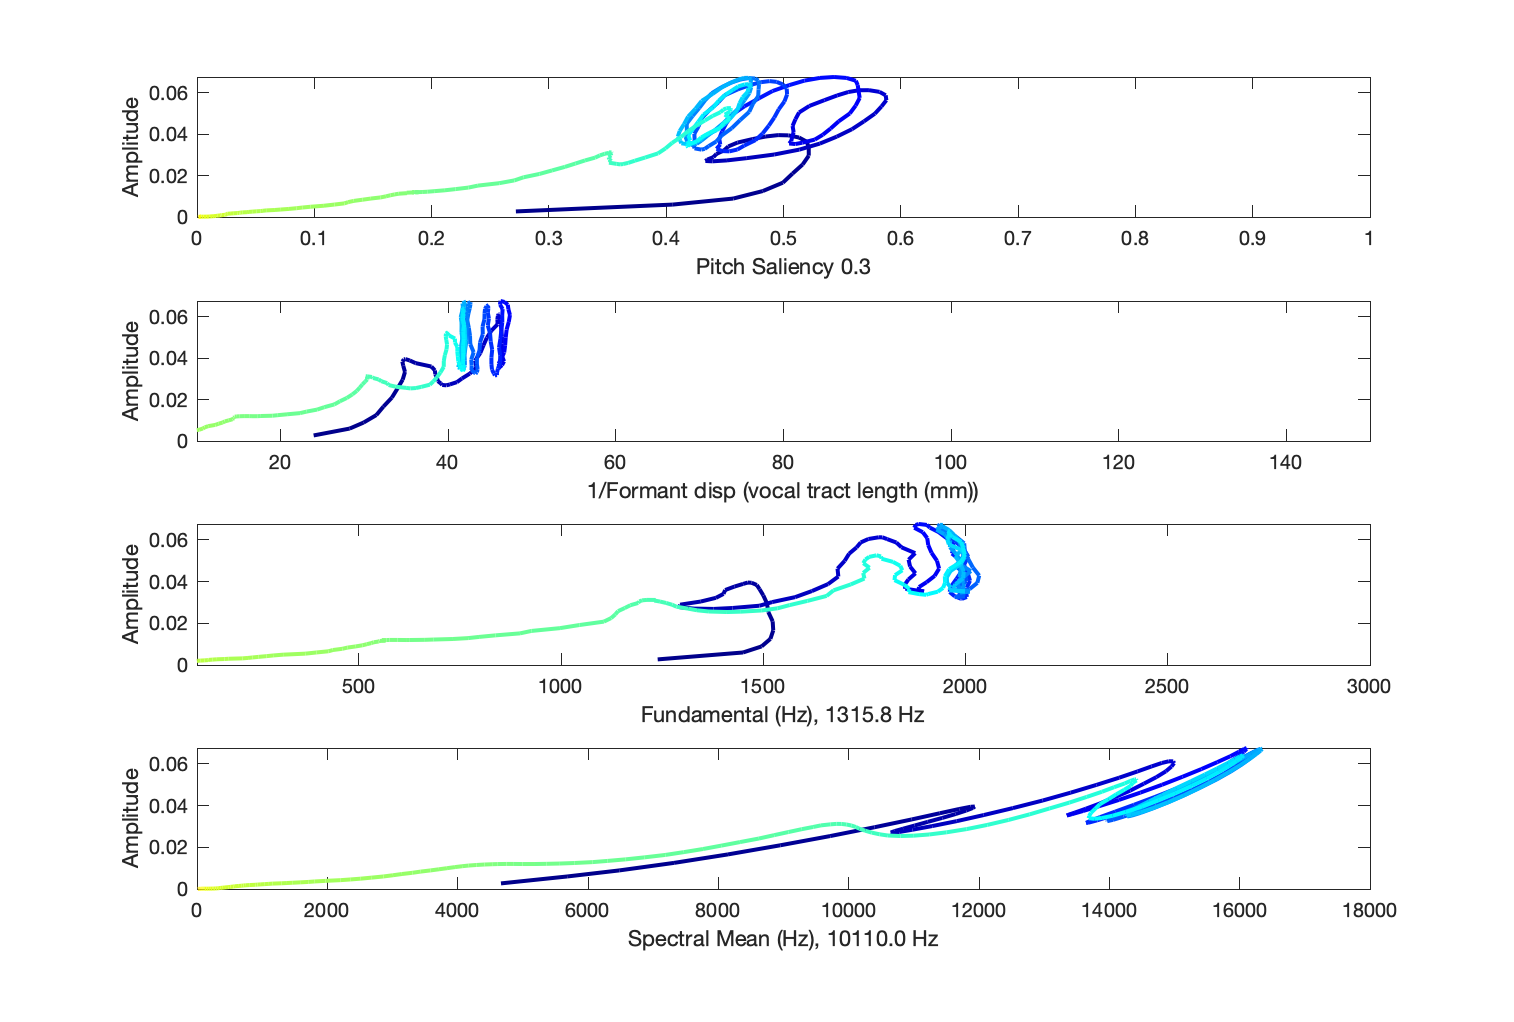

% Plot the average vocalization
HalfSpan = (Span-1)/2;
% Plot the pitch saliency vs amplitude on microphone
subplot(4,1,1)
hold off
Saliency = mean(Trills_sal_mat);
Amplitude = mean(Trills_amp_mat);
TimeSound = 1:size(Trills_sal_mat,2);
TimeSound = TimeSound./max(TimeSound);
cmap = colormap('jet');
ncolors = length(cmap);
nx = length(Saliency);

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([Saliency(ii), Saliency(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[0 1]);
xlabel(sprintf('Pitch Saliency %.1f', mean(Saliency)))
ylabel('Amplitude')
hold off

% Plot the difference of formants (Mic data) vs sound amplitude (Mic
% Data)
subplot(4,1,2)
hold off
FormantDisp = mean(Trills_formDisp_mat);
nx = length(FormantDisp);


for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([FormantDisp(ii), FormantDisp(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[10 150])
xlabel('1/Formant disp (vocal tract length (mm))')
ylabel('Amplitude')
hold off

% Plot the amplitude (Mic data) vs fundamental (Piezo
% Data)
subplot(4,1,3)
hold off
SoundFund = mean(Trills_fund_mat);
if ~isempty(SoundFund)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundFund(ii), SoundFund(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Fundamental (Hz), %.1f Hz', mean(SoundFund)))
    set(gca,'XLim',[100 3000])
end
hold off

% Plot the Amplitude (Mic data) vs SpectralMean (Mic
% Data)
subplot(4,1,4)
hold off
SoundSpecMean = mean(Trills_specMean_mat);
if ~isempty(SoundSpecMean)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundSpecMean(ii), SoundSpecMean(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Spectral Mean (Hz), %.1f Hz', mean(SoundSpecMean)))
%     set(gca,'XLim',[25000 30000])
end
hold off

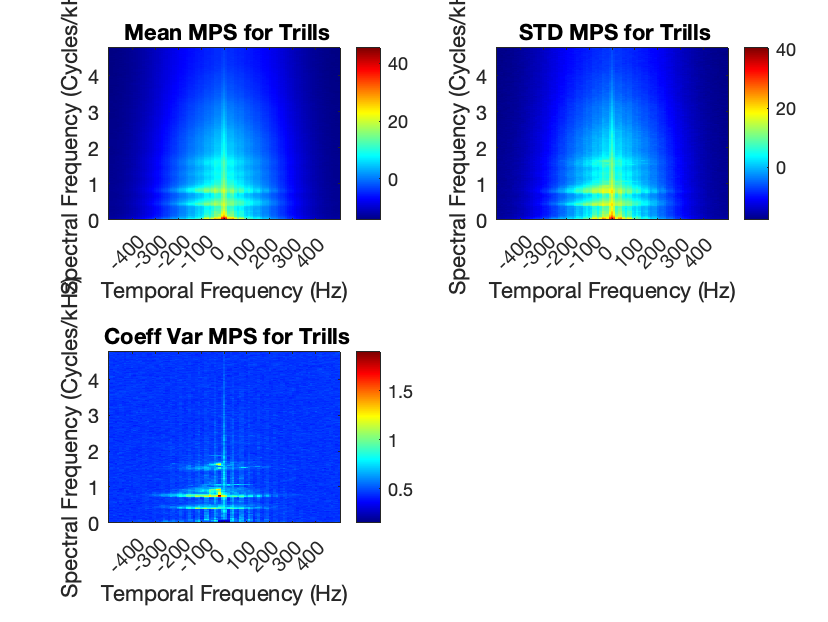

% plot the average and the STD mps
DBNOISE = 60;
figure
tiledlayout(2,2)
nexttile
MeanMPS = reshape(mean(Trills_mps_mat),length(Trills_wf), length(Trills_wt));
plot_mps(MeanMPS, Trills_wf, Trills_wt, DBNOISE);
title(' Mean MPS for Trills')

nexttile
STDMPS = reshape(std(Trills_mps_mat),length(Trills_wf), length(Trills_wt));
plot_mps(STDMPS, Trills_wf, Trills_wt, DBNOISE);
title(' STD MPS for Trills')

nexttile
VarMPS = STDMPS./MeanMPS;
plot_mps(VarMPS, Trills_wf, Trills_wt, DBNOISE,0);
title(' Coeff Var MPS for Trills')

% We want to supress the first row of the power spectrum (spectral Frequency = 0Hz) that is
% particularly noisy as we can see on the STD plot
Trills_mps_4PCA = cell(size(Trills_mps));
for cc=1:NC
    Trills_mps_4PCA{cc} = cell(size(Trills_mps{cc}));
    for Nstim = 1:length(Trills_mps{cc})
        MPS = reshape(Trills_mps{cc}{Nstim}, length(Trills_wf), length(Trills_wt));
        MPS(Trills_wf<=0,:) = []; %remove the negative values, the MPS is symmetrical around 0, and the zero raw
        Trills_mps_4PCA{cc}{Nstim} = reshape(MPS, numel(MPS),1);
    end
end
    Trills_mps_mat2 = [Trills_mps_4PCA{:}];
    Trills_mps_mat2 = [Trills_mps_mat2{:}]';

% Run PCA on the selected upper MPS
Trills_mps_centered2 = Trills_mps_mat2 - mean(Trills_mps_mat2);
[PC_mps,Score_mps,~, ~, VarExpl_mps,~] = pca(Trills_mps_centered2);

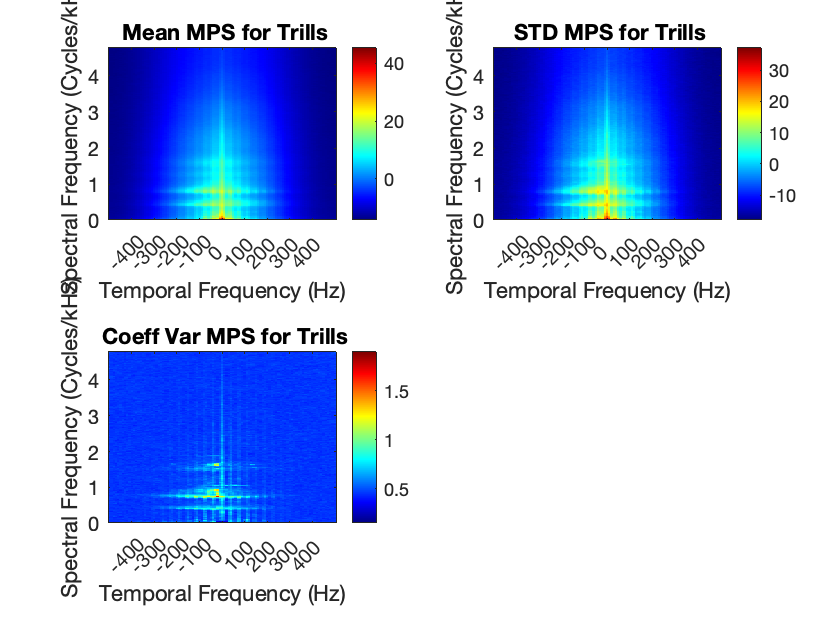

% plot the average and the STD mps now!
Trills_wf2 = Trills_wf(Trills_wf>0);
DBNOISE = 60;
figure
tiledlayout(2,2)
nexttile
MeanMPS = reshape(mean(Trills_mps_mat2),length(Trills_wf2), length(Trills_wt));
plot_mps(MeanMPS, Trills_wf2, Trills_wt, DBNOISE);
title(' Mean MPS for Trills')

nexttile
STDMPS = reshape(std(Trills_mps_mat2),length(Trills_wf2), length(Trills_wt));
plot_mps(STDMPS, Trills_wf2, Trills_wt, DBNOISE);
title(' STD MPS for Trills')

nexttile
VarMPS = STDMPS./MeanMPS;
plot_mps(VarMPS, Trills_wf2, Trills_wt, DBNOISE,0);
title(' Coeff Var MPS for Trills')

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data.mat'), 'Trills_mps_mat2','Trills_wf2', '-append')

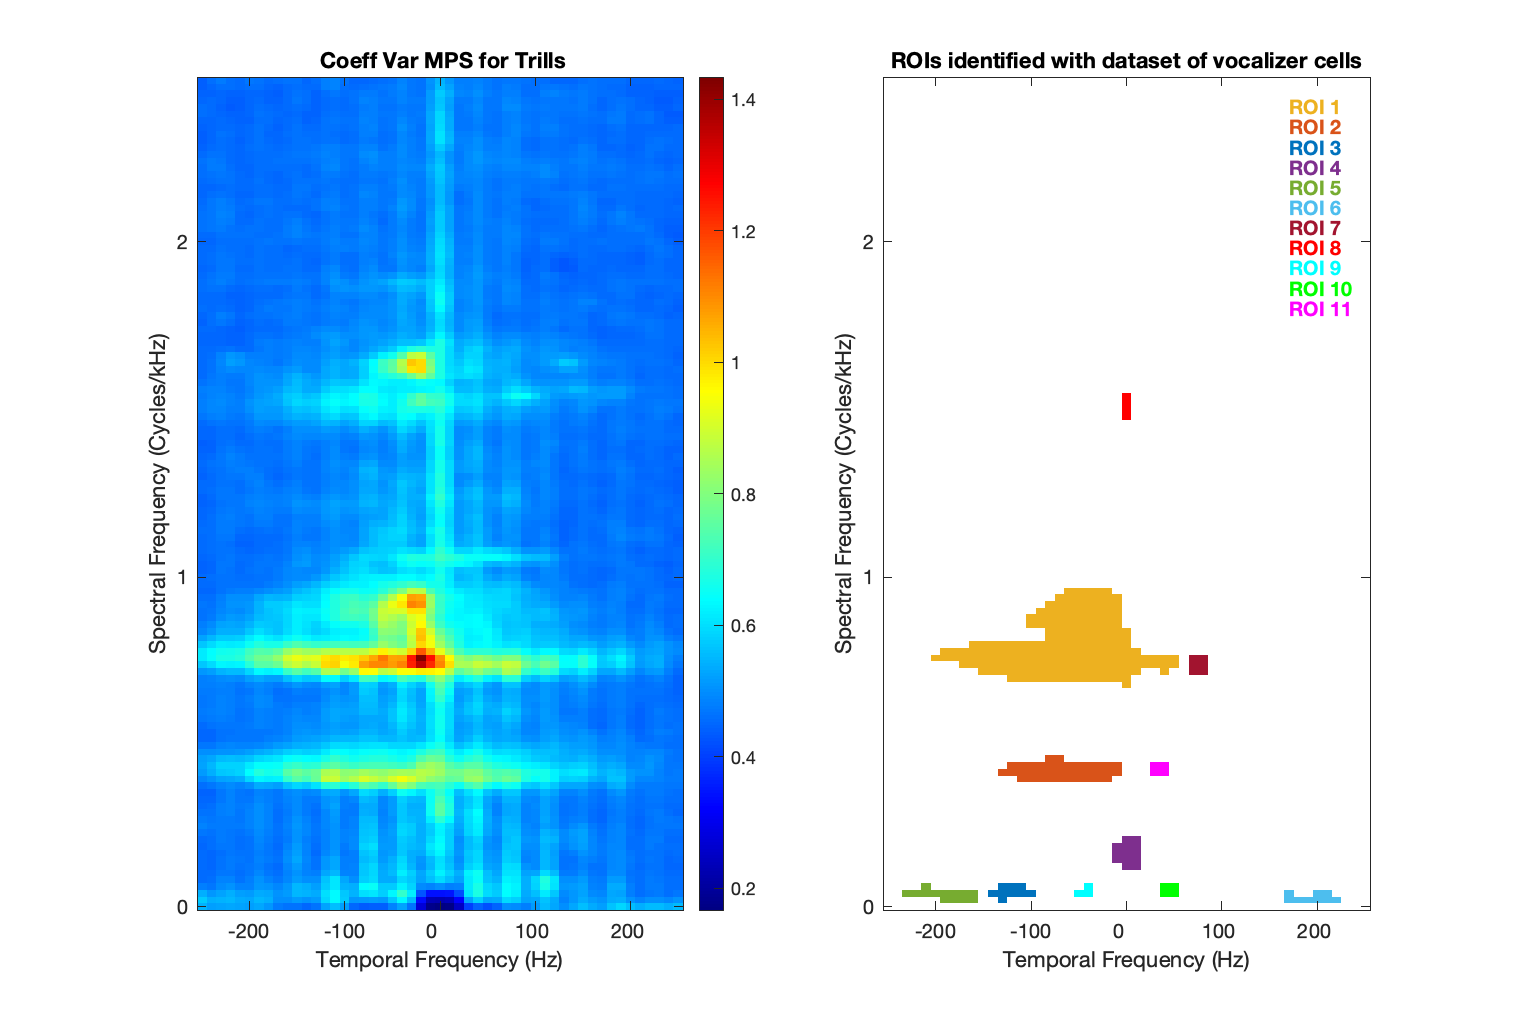

% Load the ROI calculated with thedataset of vocalizer cells
load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'),'ROI','Wf_ROI','Wt_ROI')

F=figure(5);
set(F,'Visible','on')
clf(F)
tiledlayout(1,2)
nexttile
plot_mps(VarMPS, Trills_wf2, Trills_wt, DBNOISE,0, [0 2.5], [-250 250],nan,0.75);
title(' Coeff Var MPS for Trills')


% plot ROI mapping
nexttile
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 1 0 0; 0 1 1; 0 1 0; 1 0 1];
ColorCode = ColorCode([3 2 1 4:11], :);
ROI_map = ones(size(ROI{1},1),size(ROI{1},2),3);
for rr=1:length(ROI)
    [Row, Col] = ind2sub(size(ROI{rr}),find(logical(ROI{rr})));
    for ii=1:length(Row)
        ROI_map(Row(ii),Col(ii),:) = ColorCode(rr,:);
    end
end
imagesc(ROI_map)
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_ROI*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('ROIs identified with dataset of vocalizer cells')

for rr=1:length(ROI)
    text(43, 123-3*rr, sprintf('ROI %d', rr), 'Color',ColorCode(rr,:), 'FontWeight', 'bold');
end

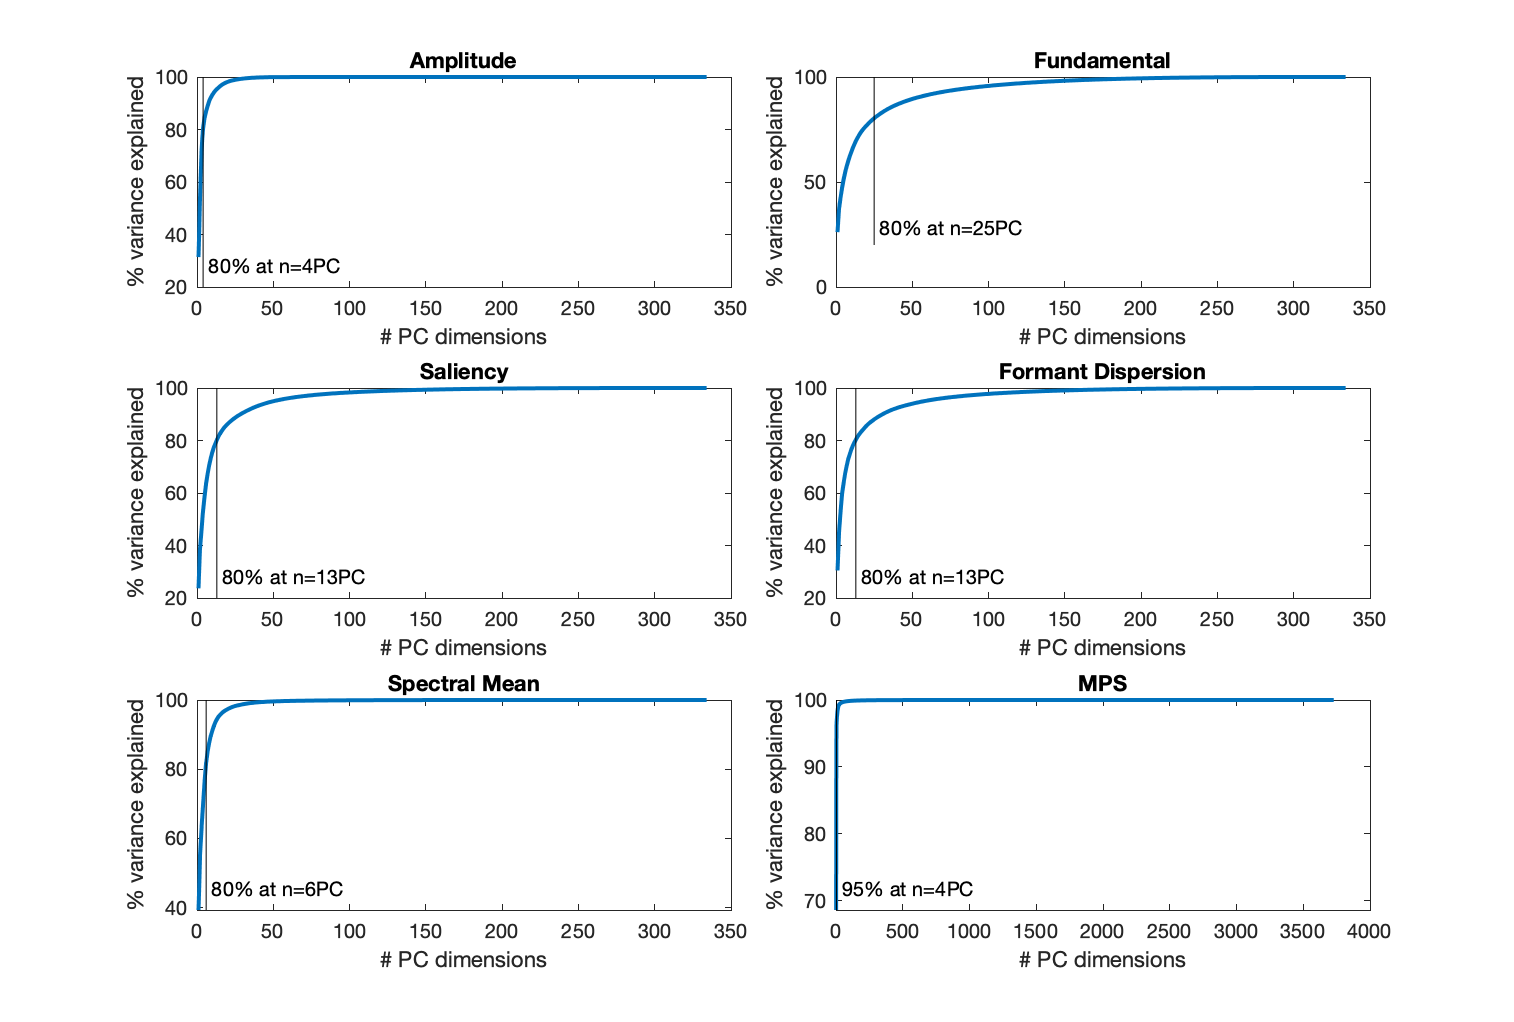

% Plot the variance explained
PercVar = 80;
t = tiledlayout(3,2,'TileSpacing','Compact');
nexttile
plot(cumsum(VarExpl_amp), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_amp)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_amp)>PercVar,1)))
hold off
title('Amplitude')

nexttile
plot(cumsum(VarExpl_fund), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_fund)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_fund)>PercVar,1)))
hold off
title('Fundamental')

nexttile
plot(cumsum(VarExpl_sal), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_sal)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_sal)>PercVar,1)))
hold off
title('Saliency')

nexttile
plot(cumsum(VarExpl_formDisp), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_formDisp)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_formDisp)>PercVar,1)))
hold off
title('Formant Dispersion')

nexttile
plot(cumsum(VarExpl_specMean), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_specMean)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_specMean)>PercVar,1)))
hold off
title('Spectral Mean')

nexttile
plot(cumsum(VarExpl_mps), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_mps)>95,1), '-k',sprintf('%d%% at n=%dPC',95, find(cumsum(VarExpl_mps)>95,1)))
hold off
title('MPS')

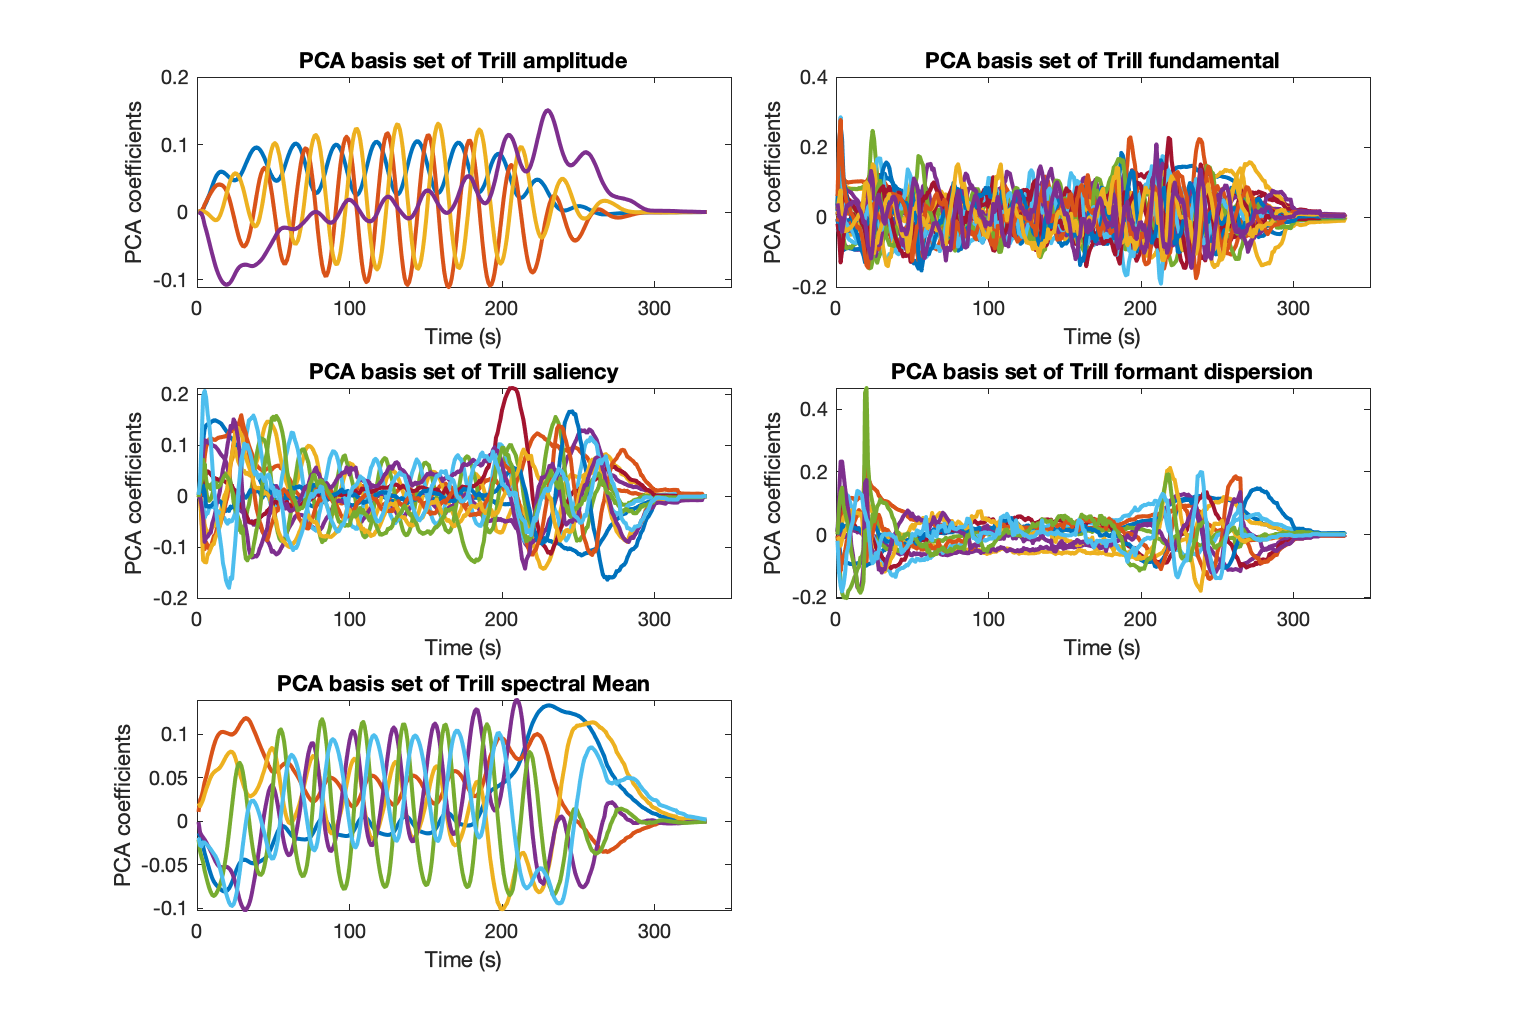

% Plot the first PC shapes
t = tiledlayout(3,2,'TileSpacing','Compact');

nexttile
NPC_amp = find(cumsum(VarExpl_amp)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_amp 
    plot(PC_amp(:,ii), 'LineWidth',2,'DisplayName', sprintf('PC%d',ii));
    hold on
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill amplitude')
hold off

nexttile
NPC_fund = find(cumsum(VarExpl_fund)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_fund 
    plot(PC_fund(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill fundamental')
hold off

nexttile
NPC_sal = find(cumsum(VarExpl_sal)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_sal 
    plot(PC_sal(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill saliency')
hold off

nexttile
NPC_formDisp = find(cumsum(VarExpl_formDisp)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_formDisp 
    plot(PC_formDisp(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill formant dispersion')
hold off

nexttile
NPC_specMean = find(cumsum(VarExpl_specMean)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_specMean 
    plot(PC_specMean(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill spectral Mean')
hold off

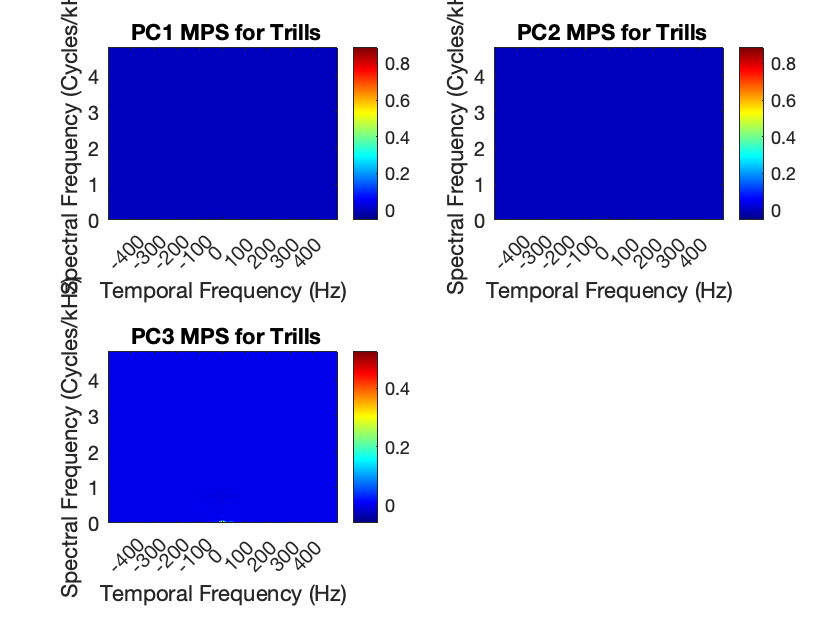


figure
tiledlayout(2,2)
nexttile
MPS_PC1 = reshape(PC_mps(:,1),length(Trills_wf2), length(Trills_wt));
plot_mps(MPS_PC1, Trills_wf2, Trills_wt, 50,0);
title(' PC1 MPS for Trills')

nexttile
MPS_PC2 = reshape(PC_mps(:,2),length(Trills_wf2), length(Trills_wt));
plot_mps(MPS_PC1, Trills_wf2, Trills_wt,50,0);
title(' PC2 MPS for Trills')

nexttile
MPS_PC3 = reshape(PC_mps(:,3),length(Trills_wf2), length(Trills_wt));
plot_mps(MPS_PC3, Trills_wf2, Trills_wt,50,0);
title(' PC3 MPS for Trills')

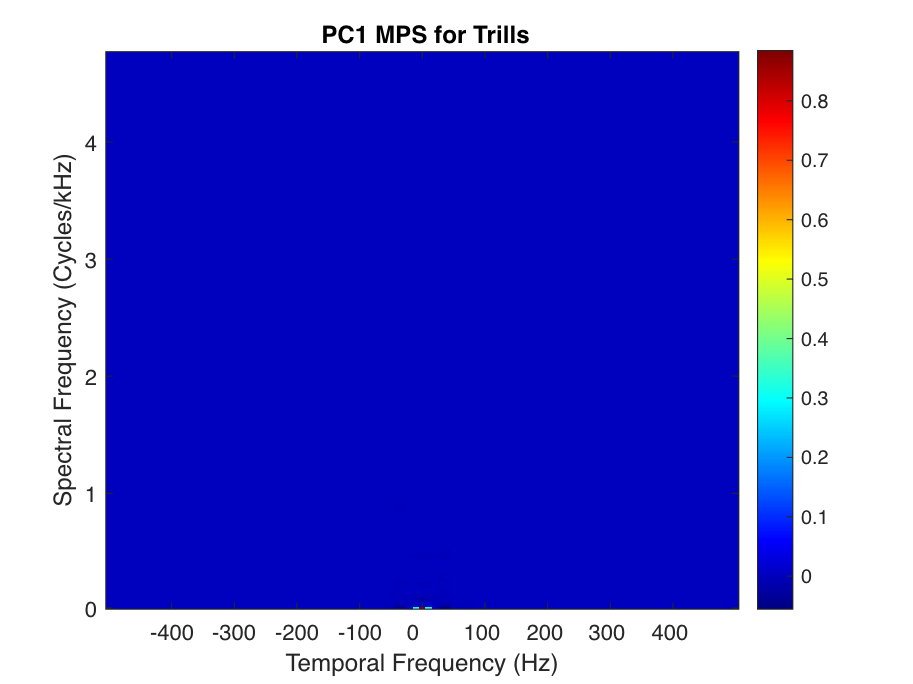

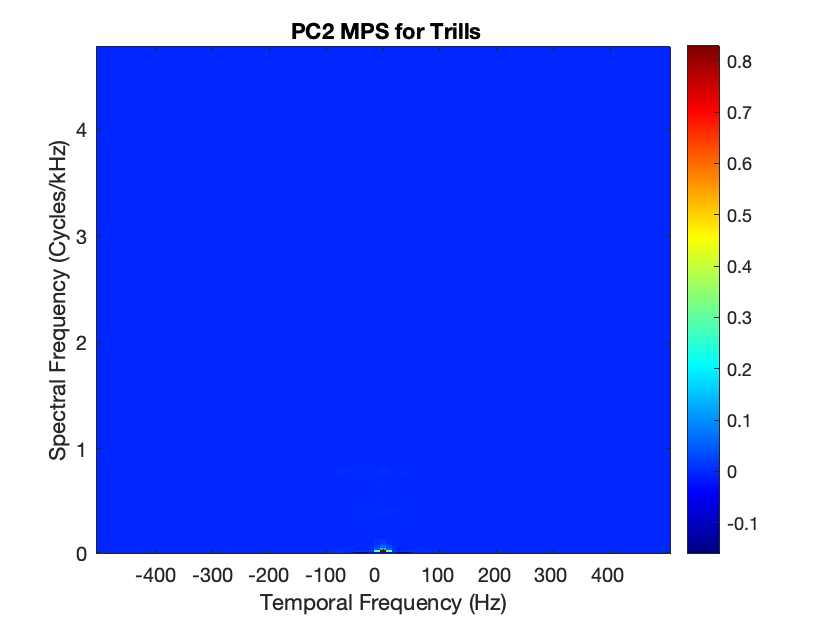

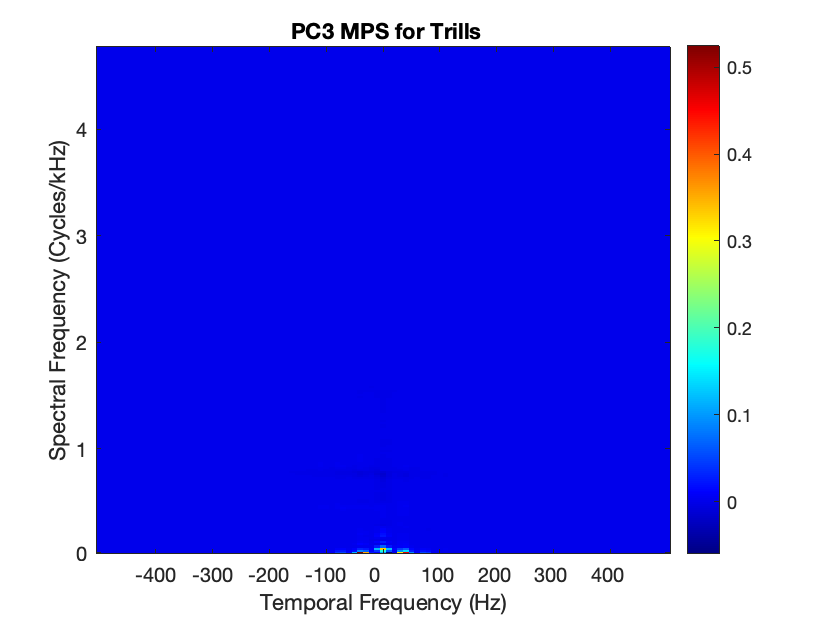

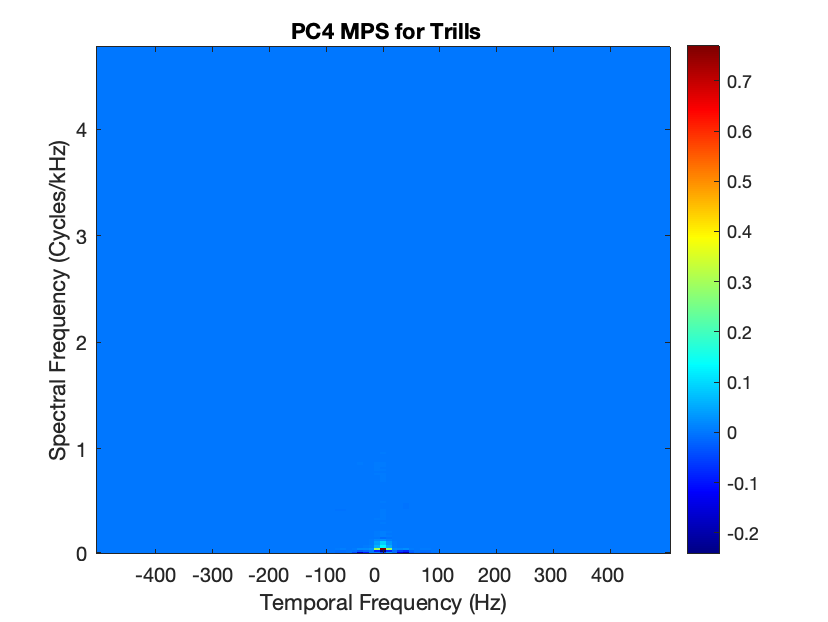

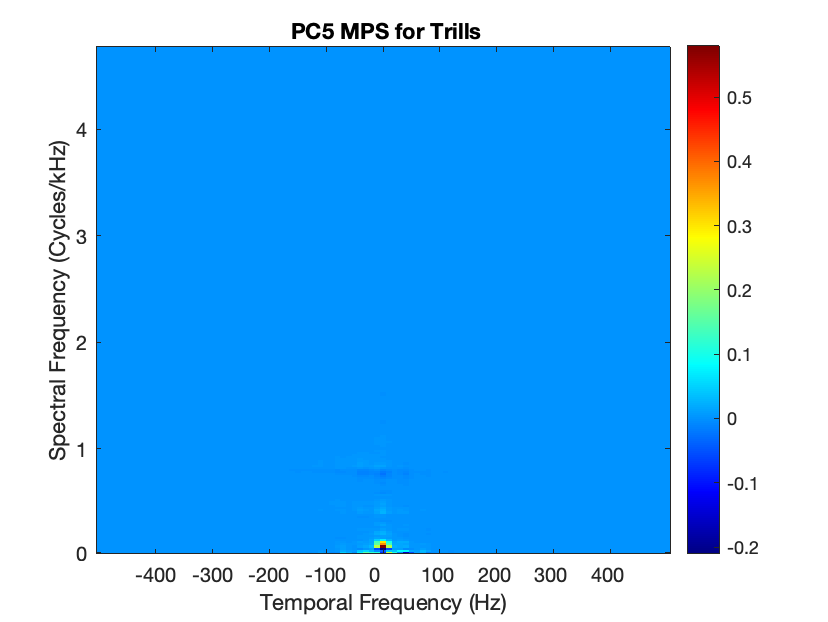

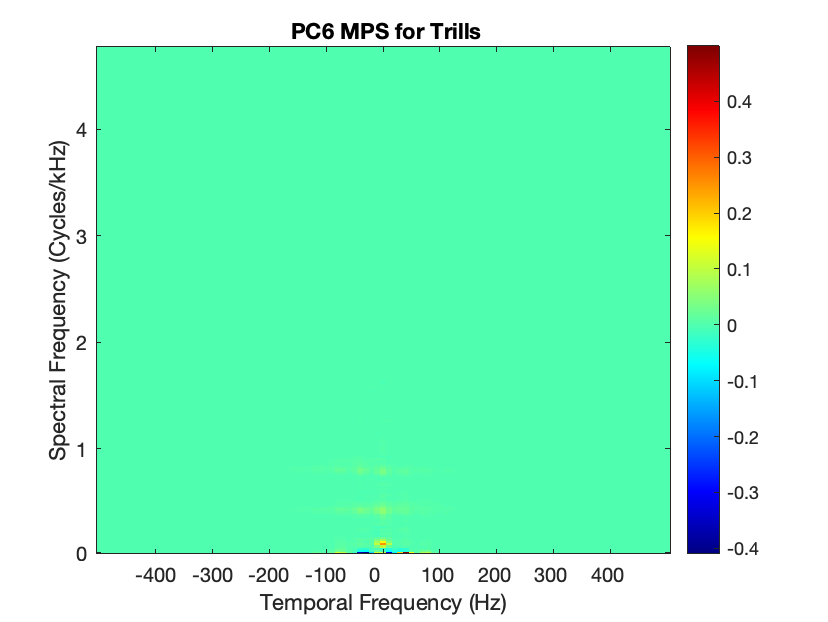

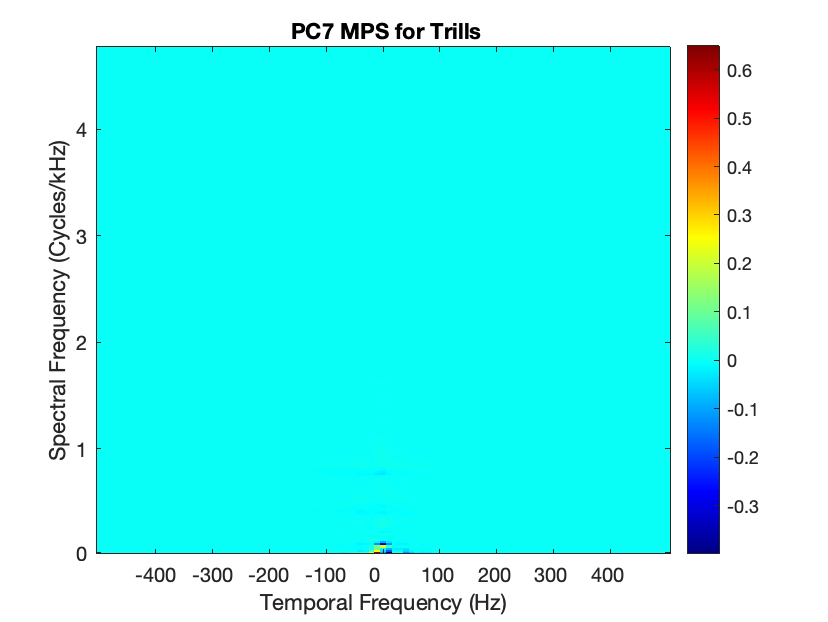

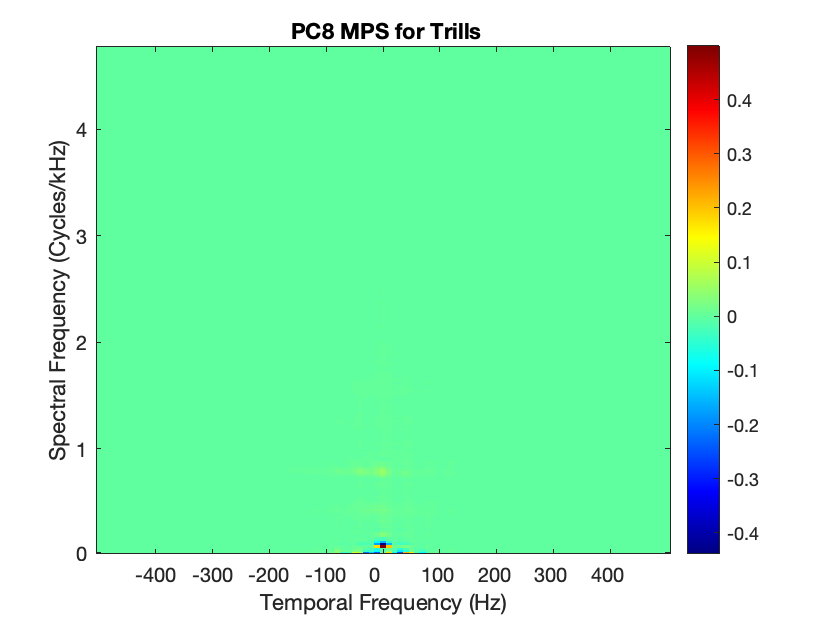

for pp = 1:20
    figure()
    MPS_PCpp = reshape(PC_mps(:,pp),length(Trills_wf2), length(Trills_wt));
    plot_mps(MPS_PCpp, Trills_wf2, Trills_wt,50,0);
    title(sprintf(' PC%d MPS for Trills', pp))
end

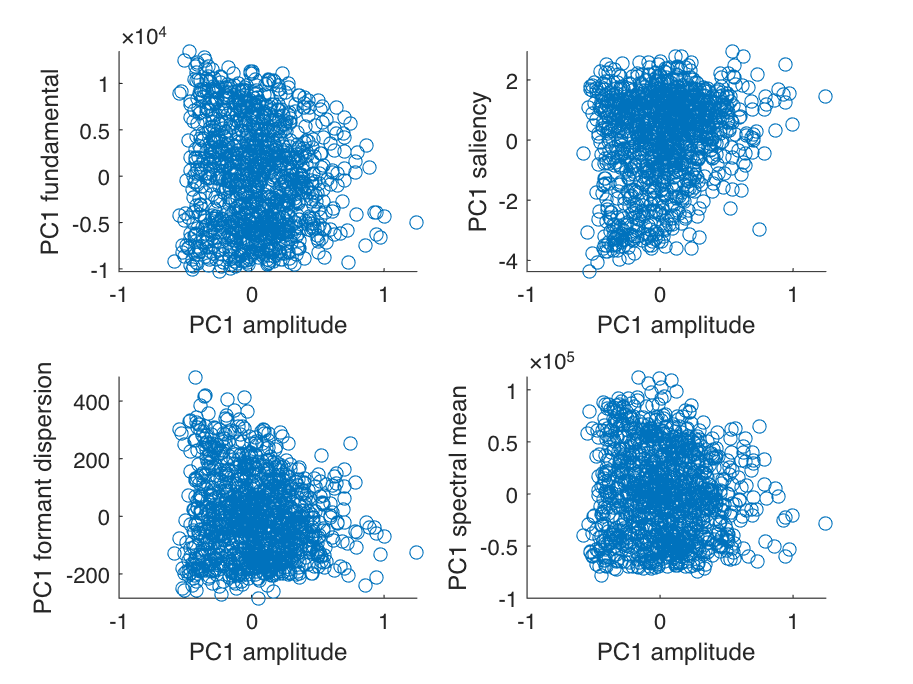

% plot all vocalizations in the first PC dimension of each acoustic feature
t = tiledlayout(2,2,'TileSpacing','Compact');
nexttile
scatter(Score_amp(:,1),Score_fund(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 fundamental')

nexttile
scatter(Score_amp(:,1),Score_sal(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 saliency')

nexttile
scatter(Score_amp(:,1),Score_formDisp(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 formant dispersion')

nexttile
scatter(Score_amp(:,1),Score_specMean(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 spectral mean')


% we can observe that formant dispersion has some outsider that might drive
% the pca weirdly...

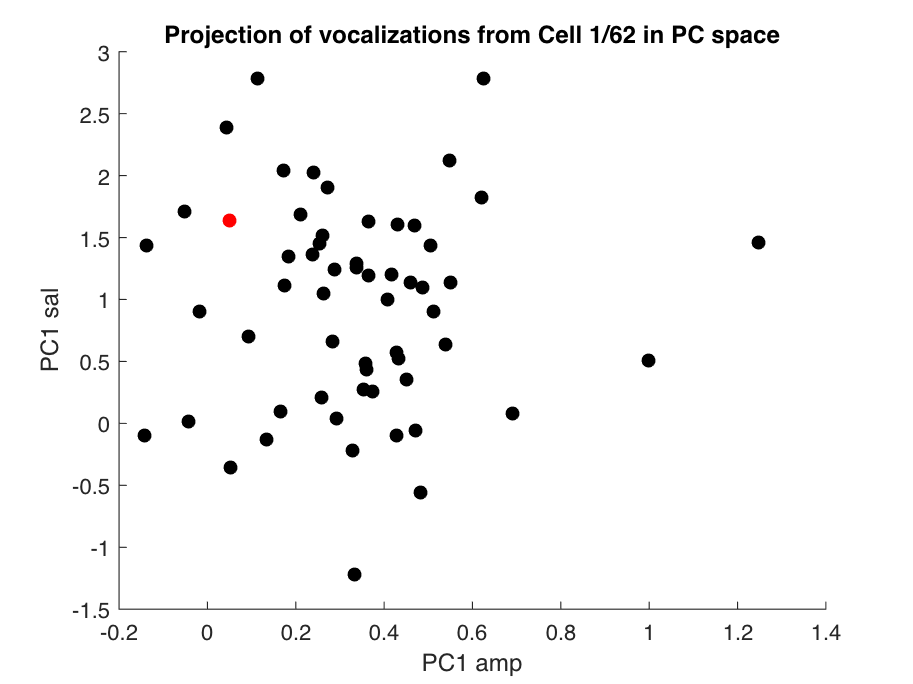

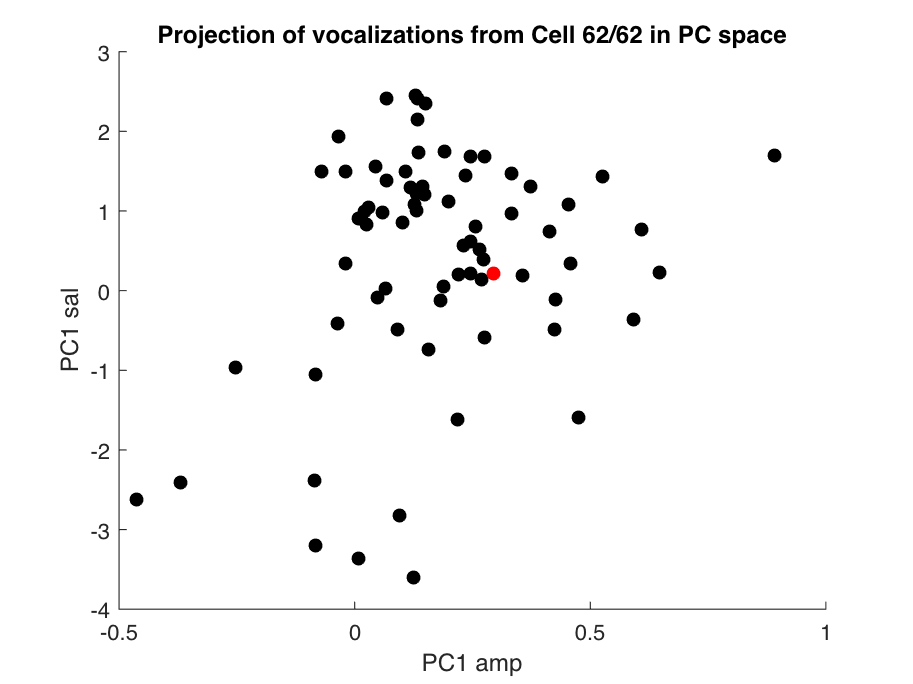

t = tiledlayout(1,1);
% Obtain the matrix of acoustic distance for each cell for each PAF and
% PCScore on PAF
% retrieve for each cell the instance that was used as a reference for neural distances
AcousticVectorDistance = cell(NC,1);
AcousticMatrixDistance = cell(NC,1);
AcousticMatrixDistance_amp = cell(NC,1);
AcousticMatrixDistance_fund = cell(NC,1);
AcousticMatrixDistance_sal = cell(NC,1);
AcousticMatrixDistance_specMean = cell(NC,1);
AcousticMatrixDistance_formDisp = cell(NC,1);
for cc=1:NC
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = [Score_amp(Row1(end)+(1:NStims(cc)),1:NPC_amp) Score_fund(Row1(end)+(1:NStims(cc)),1:NPC_fund) Score_sal(Row1(end)+(1:NStims(cc)),1:NPC_sal) Score_formDisp(Row1(end)+(1:NStims(cc)),1:NPC_formDisp) Score_specMean(Row1(end)+(1:NStims(cc)),1:NPC_specMean)];
    % Calculate euclidean distance between pairs of vocalizations in PCA
    % space
    D = squareform(pdist(Score_local, 'seuclidean'));
    % Find the observation that we used as a reference to calculate neural
    % distances
    CentralInstance = find(NeuralVectorDistance{cc} == 0);
    % Calculate the euclidean distance of all other points to the
    % reference point
    AcousticVectorDistance{cc} = D(CentralInstance(1), :);
    AcousticMatrixDistance{cc} = D;
    % Calculate euclidean distance between pairs of vocalizations in PFA
    % space
    AcousticMatrixDistance_amp{cc} = squareform(pdist(Score_amp(Row1(end)+(1:NStims(cc)),1:NPC_amp), 'seuclidean'));
    AcousticMatrixDistance_fund{cc} = squareform(pdist(Score_fund(Row1(end)+(1:NStims(cc)),1:NPC_fund), 'seuclidean'));
    AcousticMatrixDistance_sal{cc} = squareform(pdist(Score_sal(Row1(end)+(1:NStims(cc)),1:NPC_sal), 'seuclidean'));
    AcousticMatrixDistance_specMean{cc} = squareform(pdist(Score_specMean(Row1(end)+(1:NStims(cc)),1:NPC_specMean), 'seuclidean'));
    AcousticMatrixDistance_formDisp{cc} = squareform(pdist(Score_formDisp(Row1(end)+(1:NStims(cc)),1:NPC_formDisp), 'seuclidean'));
    Col = zeros(NStims(cc),3);
    Col(CentralInstance(1),:) = [1 0 0];
    scatter(Score_local(:,1),Score_local(:,NPC_amp + NPC_fund+1),40,Col, 'filled')
    xlabel('PC1 amp')
    ylabel('PC1 sal')
    title(sprintf('Projection of vocalizations from Cell %d/%d in PC space', cc, NC))
end

t = tiledlayout(1,1);

Wf_pos = logical((Trills_wf>0) .* (Trills_wf*10^3<=2.5));
Wt_narrow = logical((Trills_wt>=-250) .* (Trills_wt<=250));
% Obtain the matrix of acoustic distance in MPS space for each cell
% retrieve for each cell the instance that was used as a reference for neural distances
MPS_Norm_ROI = cell(NC,1);
AcousticMatrixDistance_mps = cell(NC,length(ROI));
for cc=1:NC
    % Calculate euclidean distance between pairs of vocalizations in MPS
    % space
    MPS_Norm_ROI{cc} = nan(NStims(cc), length(ROI));
    MeanMPS_local = mean([Trills_mps{cc}{:}],2);
    for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            AcousticMatrixDistance_mps{cc,rr} = zeros(NStims(cc));
        for ss1=1:NStims(cc)
            Mps_local1 = reshape(Trills_mps{cc}{ss1}./MeanMPS_local, length(Trills_wf), length(Trills_wt));
            MPS_local1  = Mps_local1(Wf_pos, Wt_narrow);
            MPS_vec1 = reshape(MPS_local1, numel(MPS_local1),1);
            for ss2=(ss1+1):NStims(cc)
                Mps_local2 = reshape(Trills_mps{cc}{ss2}./MeanMPS_local, length(Trills_wf), length(Trills_wt));
                MPS_local2  = Mps_local2(Wf_pos, Wt_narrow);
                MPS_vec2 = reshape(MPS_local2, numel(MPS_local2),1);
                MPS_Diff = MPS_vec1 - MPS_vec2;
                AcousticMatrixDistance_mps{cc,rr}(ss1,ss2) = mean((MPS_Diff(logical(ROI_local))).^2).^0.5;
                AcousticMatrixDistance_mps{cc,rr}(ss2,ss1) = AcousticMatrixDistance_mps{cc,rr}(ss1,ss2);
            end
        end
    end
end

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data.mat'), 'AcousticMatrixDistance', 'AcousticMatrixDistance_mps','-append')

% Now for each cell, see if there is any correlation between the distance
% of vocalization in the neural space and the distance of vocalization in
% the acoustic space
figure
Rho = nan(NC,2);
Rho_per_cell = nan(NC,2);
for cc=1:NC
    CentralInstance = find(NeuralVectorDistance{cc} == 0);
    AVD = AcousticVectorDistance{cc};
    AVD(CentralInstance) = [];
    NVD1 = NeuralVectorDistance{cc,1};
    NVD1(CentralInstance) = [];
    NVD2 = NeuralVectorDistance{cc,2};
    NVD2(CentralInstance) = [];

    tiledlayout(1,2)
    nexttile
    scatter(AVD,NVD1, 40, 'k', 'filled')
    xlabel('Acoustic distance')
    ylabel('Neural distance')
    [Rho(cc,1), Rho(cc,2)] = corr(AVD',NVD1');
    title(sprintf('Population PCA Cell %d Rho = %.2f pval = %.3f',cc, Rho(cc,1), Rho(cc,2)))
    nexttile
    scatter(AVD,NVD2, 40, 'k', 'filled')
    xlabel('Acoustic distance')
    ylabel('Neural distance')
    [Rho_per_cell(cc,1), Rho_per_cell(cc,2)] = corr(AVD',NVD2');
    title(sprintf('Individual PCA: Cell %d Rho = %.2f pval = %.3f',cc, Rho_per_cell(cc,1), Rho_per_cell(cc,2)))
    pause()
    
end
fprintf(1, 'There are %d/%d cells for which Acoustic and Neural distances (one row of the matrix excluding the reference vocalization) are significantly correlated at 0.05', sum(Rho(:,2)<0.05), NC)

% Run a Mantel test between matrices of Distance to find cells with
% significantly similar neural and acoustic matrices
Mantel_PCApop = nan(NC,4);
Mantel_PCAper_cell = nan(NC,4);
Mantel_mps_PCApop = nan(NC,length(ROI),4);
Mantel_mps_PCAper_cell = nan(NC,length(ROI),4);
Mantel_mps_ZSRate = nan(NC,length(ROI),4);
Mantel_mps_ZSRatePCAper_cell = nan(NC,length(ROI),4);
for cc=1:NC
    [Mantel_PCApop(cc,1), Mantel_PCApop(cc,2), Mantel_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance{cc});
    Mantel_PCApop(cc,4) = r(1,2);
    [Mantel_PCAper_cell(cc,1), Mantel_PCAper_cell(cc,2), Mantel_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance{cc});
    Mantel_PCAper_cell(cc,4) = r(1,2);
    for rr=1:length(ROI)
        [Mantel_mps_PCApop(cc,rr,1), Mantel_mps_PCApop(cc,rr,2), Mantel_mps_PCApop(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_mps{cc,rr});
        Mantel_mps_PCApop(cc,rr,4) = r(1,2);
        [Mantel_mps_PCAper_cell(cc,rr,1), Mantel_mps_PCAper_cell(cc,rr,2), Mantel_mps_PCAper_cell(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_mps{cc,rr});
        Mantel_mps_PCAper_cell(cc,rr,4) = r(1,2);
        [Mantel_mps_ZSRate(cc,rr,1), Mantel_mps_ZSRate(cc,rr,2), Mantel_mps_ZSRate(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_mps{cc,rr});
        Mantel_mps_ZSRate(cc,rr,4) = r(1,2);
        [Mantel_mps_ZSRatePCAper_cell(cc,rr,1), Mantel_mps_ZSRatePCAper_cell(cc,rr,2), Mantel_mps_ZSRatePCAper_cell(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_mps{cc,rr});
        Mantel_mps_ZSRatePCAper_cell(cc,rr,4) = r(1,2);
    end
end

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_ListTrills_data.mat'),'Mantel_mps_PCApop','Mantel_mps_PCAper_cell','Mantel_mps_ZSRate','Mantel_mps_ZSRatePCAper_cell','-append');

fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Cell population PCA)', sum(Mantel_PCApop(:,2)<0.05), NC)

There are 1/62 cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Cell population PCA)

ListCellsList{Mantel_PCApop(:,2)<0.05}

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Individual Cell PCA)', sum(Mantel_PCAper_cell(:,2)<0.05), NC)

There are 0/62 cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Individual Cell PCA)

ListCellsList{Mantel_PCAper_cell(:,2)<0.05}
Mantel_mps_PCApop_pval = nan(NC,length(ROI));
Mantel_mps_PCAper_cell_pval = nan(NC,length(ROI));
Mantel_mps_ZSRate_pval = nan(NC,length(ROI));
Mantel_mps_ZSRatePCAper_cell_pval = nan(NC,length(ROI));
Mantel_mps_PCApop_r = nan(NC,length(ROI));
Mantel_mps_PCAper_cell_r = nan(NC,length(ROI));
Mantel_mps_ZSRate_r = nan(NC,length(ROI));
Mantel_mps_ZSRatePCAper_cell_r = nan(NC,length(ROI));
for rr=1:length(ROI)
    fprintf(1, '/n/n***** ROI %d/%d **********/n', rr, length(ROI))
    fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)', sum(Mantel_mps_PCApop(:,rr,2)<0.05), NC)
    ListCellsList{Mantel_mps_PCApop(:,rr,2)<0.05}
    Mantel_mps_PCApop_pval(:,rr) = Mantel_mps_PCApop(:,rr,2);
    Mantel_mps_PCApop_r(:,rr) = Mantel_mps_PCApop(:,rr,4);
    fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)', sum(Mantel_mps_PCAper_cell(:,rr,2)<0.05), NC)
    ListCellsList{Mantel_mps_PCAper_cell(:,rr,2)<0.05}
    Mantel_mps_PCAper_cell_pval(:,rr) = Mantel_mps_PCAper_cell(:,rr,2);
    Mantel_mps_PCAper_cell_r(:,rr) = Mantel_mps_PCAper_cell(:,rr,4);
    fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)', sum(Mantel_mps_ZSRate(:,rr,2)<0.05), NC)
    ListCellsList{Mantel_mps_ZSRate(:,rr,2)<0.05}
    Mantel_mps_ZSRate_pval(:,rr) = Mantel_mps_ZSRate(:,rr,2);
    Mantel_mps_ZSRate_r(:,rr) = Mantel_mps_ZSRate(:,rr,4);
    fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)', sum(Mantel_mps_ZSRatePCAper_cell(:,rr,2)<0.05), NC)
    ListCellsList{Mantel_mps_ZSRatePCAper_cell(:,rr,2)<0.05}
    Mantel_mps_ZSRatePCAper_cell_pval(:,rr) = Mantel_mps_ZSRatePCAper_cell(:,rr,2);
    Mantel_mps_ZSRatePCAper_cell_r(:,rr) = Mantel_mps_ZSRatePCAper_cell(:,rr,4);
end

/n/n***** ROI 1/11 **********/n

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-97.mat'

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-169.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_1-134.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_1-127.mat'

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

/n/n***** ROI 2/11 **********/n

There are 8/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_4-183.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-185.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_2-139.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSM_1-109.mat'

There are 6/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-185.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_1-127.mat'

There are 7/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_2-189.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-185.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_3-190.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_1-75.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_2-139.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

There are 6/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-185.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_1-127.mat'

/n/n***** ROI 3/11 **********/n

There are 1/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-205.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_2-88.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

/n/n***** ROI 4/11 **********/n

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_2-189.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_2-139.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSS_1-174.mat'

There are 1/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

/n/n***** ROI 5/11 **********/n

There are 4/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSS_1-174.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_1-80.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSM_1-109.mat'

There are 2/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_3-190.mat'

There are 1/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_1-134.mat'

There are 1/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_3-190.mat'

/n/n***** ROI 6/11 **********/n

There are 1/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-169.mat'

There are 4/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190704_SSM_4-209.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-169.mat'

/n/n***** ROI 7/11 **********/n

There are 6/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-204.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-169.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_2-139.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_2-273.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-204.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_3-236.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-204.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSM_4-229.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_2-139.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

There are 4/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_3-236.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-204.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

/n/n***** ROI 8/11 **********/n

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-202.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_1-80.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-97.mat'

There are 3/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-97.mat'

There are 4/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_1-80.mat'

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSM_3-278.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-110.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_1-80.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSS_1-97.mat'

/n/n***** ROI 9/11 **********/n

There are 8/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSS_1-71.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_2-189.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_2-88.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_1-75.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

There are 6/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSS_1-71.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_2-189.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_1-75.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

There are 6/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_2-189.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_2-88.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_1-75.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

There are 7/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSS_1-71.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_2-189.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190627_SSS_1-75.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

/n/n***** ROI 10/11 **********/n

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190701_SSS_2-259.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-205.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-160.mat'

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSS_1-71.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-205.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-160.mat'

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-205.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190621_SSS_2-99.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-121.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_1-86.mat'

There are 4/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190622_SSS_1-71.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190620_SSS_2-168.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-205.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-160.mat'

/n/n***** ROI 11/11 **********/n

There are 4/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Cell population PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSS_1-174.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-202.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_1-127.mat'

There are 7/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_3-190.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSS_1-174.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190623_SSS_1-169.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-202.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_2-206.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-185.mat'

There are 5/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-205.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-202.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190614_SSS_2-150.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_1-127.mat'

There are 7/62 cells for which the Mantel test on all pairs of Acoustic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)

ans = '/Volumes/JulieE8T/LMCResults/65701_20190705_SSS_2-149.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSM_3-190.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSS_1-174.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190708_SSM_4-202.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190613_SSM_2-206.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190625_SSS_2-185.mat'

ans = '/Volumes/JulieE8T/LMCResults/65701_20190624_SSM_1-127.mat'

fprintf(1, '%d/%d cells have at least one significant ROI with per Cell PCA', sum(sum(Mantel_mps_PCAper_cell_pval<0.05,2)>0),NC)

26/62 cells have at least one significant ROI with per Cell PCA

fprintf(1, '%d/%d cells have at least one significant ROI with population PCA', sum(sum(Mantel_mps_PCApop_pval<0.05,2)>0),NC)

28/62 cells have at least one significant ROI with population PCA

fprintf(1, '%d/%d cells have at least one significant ROI with ZSRate', sum(sum(Mantel_mps_ZSRate_pval<0.05,2)>0),NC)

27/62 cells have at least one significant ROI with ZSRate

fprintf(1, '%d/%d cells have at least one significant ROI with ZSRate + per Cell PCA', sum(sum(Mantel_mps_ZSRatePCAper_cell_pval<0.05,2)>0),NC)

28/62 cells have at least one significant ROI with ZSRate + per Cell PCA

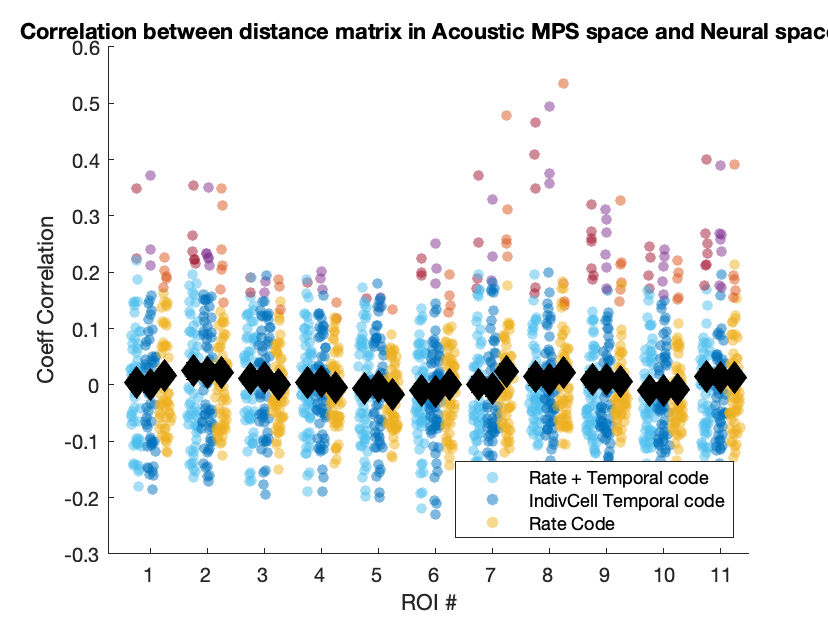

% Plot the Coeff correlation between the matrices elements and the
% significance of the Mantel test per ROI for each cell calculated with PCA
% indiv cells + ZSRate, PCA indiv cells and ZSRate
ScatterMarkerSz=30;
MeanMarkerSize=12;
figure();
for rr=1:length(ROI)
    ColZSIndT = (Mantel_mps_ZSRatePCAper_cell(:,rr,2)<0.05)*ColorCode(7,:) + (Mantel_mps_ZSRatePCAper_cell(:,rr,2)>=0.05)*ColorCode(6,:);
    swarmchart((4*rr-2)*ones(NC,1),Mantel_mps_ZSRatePCAper_cell(:,rr,4),ScatterMarkerSz,ColZSIndT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    ColZSIndNT = (Mantel_mps_PCAper_cell(:,rr,2)<0.05)*ColorCode(4,:) + (Mantel_mps_PCAper_cell(:,rr,2)>=0.05)*ColorCode(3,:);
    swarmchart((4*rr-1)*ones(NC,1),Mantel_mps_PCAper_cell(:,rr,4),ScatterMarkerSz,ColZSIndNT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    ColZS = (Mantel_mps_ZSRate(:,rr,2)<0.05)*ColorCode(2,:) + (Mantel_mps_ZSRate(:,rr,2)>=0.05)*ColorCode(1,:);
    swarmchart((4*rr)*ones(NC,1),Mantel_mps_ZSRate(:,rr,4),ScatterMarkerSz,ColZS,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    if rr==1
        legend({'Rate + Temporal code', 'IndivCell Temporal code', 'Rate Code'})
        legend('Location', 'SouthEast','AutoUpdate','off')
    end
    errorbar((4*rr-2),nanmean(Mantel_mps_ZSRatePCAper_cell(:,rr,4)),nanstd(Mantel_mps_ZSRatePCAper_cell(:,rr,4))/NC^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
    hold on
    errorbar((4*rr-1),nanmean(Mantel_mps_PCAper_cell(:,rr,4)),nanstd(Mantel_mps_PCAper_cell(:,rr,4))/NC^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
    hold on
    errorbar((4*rr),nanmean(Mantel_mps_ZSRate(:,rr,4)),nanstd(Mantel_mps_ZSRate(:,rr,4))/NC^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
    hold on
end

set(gca, 'XTick', 4*(1:length(ROI))-1, 'XTickLabel',1:length(ROI))
xlabel('ROI #')
ylabel('Coeff Correlation')
title('Correlation between distance matrix in Acoustic MPS space and Neural space')
hold off


% tiledlayout(1,2)
% nexttile
% Col = [Mantel_mps_PCApop(:,:,2)<0.05 Mantel_mps_ZSRate(:,:,2)<0.05 zeros(NC,1)];
% scatter(Mantel_mps_PCApop(:,4),Mantel_mps_ZSRate(:,4),40, Col,"filled"); xlabel('Coeff Corr PCA'); ylabel('Coeff Corr ZSRate')
% title('Cell population PCA')
% nexttile
% Col = [Mantel_PCAper_cell(:,2)<0.05 Mantel_mps_ZSRate(:,2)<0.05 zeros(NC,1)];
% scatter(Mantel_PCAper_cell(:,4),Mantel_mps_ZSRate(:,4),40, Col,"filled"); xlabel('Coeff Corr PCA'); ylabel('Coeff Corr ZSRate')
% title('Individual Cell PCA')

% Plot the Coeff correlation between the matrices elements and the
% significance of the Mantel test per ROI for each cell calculated with PCA
% indiv cells and ZSRate sorting cells between the ones with high Mahal
% distance and the ones for which we don't know
load(fullfile(Path2AllData,'explore_populationSU_data.mat'),'MahalDistanceV2','VCells')
TCells = find(VCells(logical(VCells(:,1)),3)>0);
NTCells = find((VCells(logical(VCells(:,1)),3)==0) +  (VCells(logical(VCells(:,1)),3)==2));
ScatterMarkerSz=30;
MeanMarkerSize=12;
figure();
for rr=1:length(ROI)
    
    ColZSIndT = (Mantel_mps_ZSRatePCAper_cell(TCells,rr,2)<0.05)*ColorCode(2,:) + (Mantel_mps_ZSRatePCAper_cell(TCells,rr,2)>=0.05)*ColorCode(1,:);
    swarmchart((3*rr-1)*ones(length(TCells),1),Mantel_mps_ZSRatePCAper_cell(TCells,rr,4),ScatterMarkerSz,ColZSIndT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    
    ColZSIndNT = (Mantel_mps_ZSRatePCAper_cell(NTCells,rr,2)<0.05)*ColorCode(4,:) + (Mantel_mps_ZSRatePCAper_cell(NTCells,rr,2)>=0.05)*ColorCode(3,:);
    swarmchart((3*rr)*ones(length(NTCells),1),Mantel_mps_PCAper_cell(NTCells,rr,4),ScatterMarkerSz,ColZSIndNT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    if rr==1
        legend({'Trills Mahal +', 'Trills Mahal Nan'})
        legend('Location', 'SouthEast','AutoUpdate','off')
    end
    errorbar((3*rr-1),nanmean(Mantel_mps_ZSRatePCAper_cell(TCells,rr,4)),nanstd(Mantel_mps_ZSRatePCAper_cell(TCells,rr,4))/length(TCells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
    hold on
    errorbar((3*rr),nanmean(Mantel_mps_ZSRatePCAper_cell(NTCells,rr,4)),nanstd(Mantel_mps_ZSRatePCAper_cell(NTCells,rr,4))/length(NTCells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
    hold on
end

set(gca, 'XTick', 4*(1:length(ROI))-1, 'XTickLabel',1:length(ROI))
xlabel('ROI #')
ylabel('Coeff Correlation')
title('Correlation between distance matrix in Acoustic MPS space and Neural space (Rate + Temporal)')
hold off

% Run Mantel tests on Distance matrices obtained only with some of the
% acoustic features
Mantel_amp = nan(NC,4);
Mantel_fund = nan(NC,4);
Mantel_specMean = nan(NC,4);
Mantel_sal = nan(NC,4);
Mantel_formDisp = nan(NC,4);
Mantel_amp_per_cell = nan(NC,4);
Mantel_fund_per_cell = nan(NC,4);
Mantel_specMean_per_cell = nan(NC,4);
Mantel_sal_per_cell = nan(NC,4);
Mantel_formDisp_per_cell = nan(NC,4);
for cc=1:NC
    [Mantel_amp(cc,1), Mantel_amp(cc,2), Mantel_amp(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_amp{cc});
    Mantel_amp(cc,4) = r(1,2);
    [Mantel_sal(cc,1), Mantel_sal(cc,2), Mantel_sal(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_sal{cc});
    Mantel_sal(cc,4) = r(1,2);
    [Mantel_fund(cc,1), Mantel_fund(cc,2), Mantel_fund(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_fund{cc});
    Mantel_fund(cc,4) = r(1,2);
    [Mantel_specMean(cc,1), Mantel_specMean(cc,2), Mantel_specMean(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_specMean{cc});
    Mantel_specMean(cc,4) = r(1,2);
    [Mantel_formDisp(cc,1), Mantel_formDisp(cc,2), Mantel_formDisp(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_formDisp{cc});
    Mantel_formDisp(cc,4) = r(1,2);

    [Mantel_amp_per_cell(cc,1), Mantel_amp_per_cell(cc,2), Mantel_amp_per_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_amp{cc});
    Mantel_amp_per_cell(cc,4) = r(1,2);
    [Mantel_sal_per_cell(cc,1), Mantel_sal_per_cell(cc,2), Mantel_sal_per_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_sal{cc});
    Mantel_sal_per_cell(cc,4) = r(1,2);
    [Mantel_fund_per_cell(cc,1), Mantel_fund_per_cell(cc,2), Mantel_fund_per_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_fund{cc});
    Mantel_fund_per_cell(cc,4) = r(1,2);
    [Mantel_specMean_per_cell(cc,1), Mantel_specMean_per_cell(cc,2), Mantel_specMean_per_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_specMean{cc});
    Mantel_specMean_per_cell(cc,4) = r(1,2);
    [Mantel_formDisp_per_cell(cc,1), Mantel_formDisp_per_cell(cc,2), Mantel_formDisp_per_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_formDisp{cc});
    Mantel_formDisp_per_cell(cc,4) = r(1,2);
end
fprintf(1, 'Cell Population PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp(:,2)<0.05), NC)
ListCellsList{Mantel_amp(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_per_cell(:,2)<0.05), NC)
ListCellsList{Mantel_amp_per_cell(:,2)<0.05}
fprintf(1, 'Cell Population PCA:There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal(:,2)<0.05), NC)
ListCellsList{Mantel_sal(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_per_cell(:,2)<0.05), NC)
ListCellsList{Mantel_sal_per_cell(:,2)<0.05}
fprintf(1, 'Cell Population PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund(:,2)<0.05), NC)
ListCellsList{Mantel_fund(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_per_cell(:,2)<0.05), NC)
ListCellsList{Mantel_fund_per_cell(:,2)<0.05}
fprintf(1, 'Cell population PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean(:,2)<0.05), NC)
ListCellsList{Mantel_specMean(:,2)<0.05}
fprintf(1, 'Individal cell PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_per_cell(:,2)<0.05), NC)
ListCellsList{Mantel_specMean_per_cell(:,2)<0.05}
fprintf(1, 'Cell population PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp(:,2)<0.05), NC)
ListCellsList{Mantel_formDisp(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_per_cell(:,2)<0.05), NC)
ListCellsList{Mantel_formDisp_per_cell(:,2)<0.05}

% Plot the Mantel statistics for all cells
t = tiledlayout(3,2,'TileSpacing','Compact');
nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_amp(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_amp(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Amplitude')
title('Amplitude')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_fund(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_fund(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Fundamental')
title('Fundamental')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_sal(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_sal(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Saliency')
title('Saliency')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_specMean(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_specMean(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel spectral mean')
title('Spectral mean')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_formDisp(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_formDisp(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel formant Dispersion')
title('Formants dispersion')

% Look in more details the significant cells neural responses
% amplitude cells
% plot the matrices of acoustic and neural distances side by side
fprintf(1,'Matrices of distance for significant amplitude cells')
Amp_cells = find(Mantel_amp(:,2)<0.05);
t = tiledlayout(length(Amp_cells),2);
for cc=1:length(Amp_cells)
    ListCellsList{Amp_cells(cc)}
    nexttile
    imagesc(AcousticMatrixDistance_amp{Amp_cells(cc)})
    colorbar()
    title('Amplitude')
    nexttile
    imagesc(NeuralMatrixDistance{Amp_cells(cc)})
    colorbar()
    title('Neural')

end

pThresh = 0.01;
% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Amp_cells = unique([find(Mantel_amp(:,2)<pThresh); find(Mantel_amp_per_cell(:,2)<pThresh)]);
for cc=1:length(Amp_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Amp_cells(cc)~=1
        Row1 = cumsum(NStims(1:Amp_cells(cc)-1));
    elseif Amp_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(Amp_cells(cc))),1:NPC);
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(Amp_cells(cc))),:);
    Trills_amp_mat_local = Trills_amp_mat(Row1(end)+(1:NStims(Amp_cells(cc))),:);
    Score_local2 = Score_per_cell{Amp_cells(cc)}(:,1:NPC_per_cell(Amp_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_amp_mat_local,  NeuralMatrixDistance{Amp_cells(cc),1}, AcousticMatrixDistance_amp{Amp_cells(cc)}, Amplitude, 'Amplitude')
    suplabel(sprintf('Pop PCA %s r = %.3f  p = %.4f', ListCellsList{Amp_cells(cc)},Mantel_amp(Amp_cells(cc),4),Mantel_amp(Amp_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_amp_mat_local,  NeuralMatrixDistance{Amp_cells(cc),2}, AcousticMatrixDistance_amp{Amp_cells(cc)}, Amplitude, 'Amplitude')
    suplabel(sprintf('Cell PCA %s r = %.3f  p = %.4f', ListCellsList{Amp_cells(cc)},Mantel_amp_per_cell(Amp_cells(cc),4),Mantel_amp_per_cell(Amp_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Sal_cells = unique([find(Mantel_sal(:,2)<pThresh); find(Mantel_sal_per_cell(:,2)<pThresh)]);
for cc=1:length(Sal_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Sal_cells(cc)~=1
        Row1 = cumsum(NStims(1:Sal_cells(cc)-1));
    elseif Sal_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(Sal_cells(cc))),1:NPC);
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(Sal_cells(cc))),:);
    Trills_sal_mat_local = Trills_sal_mat(Row1(end)+(1:NStims(Sal_cells(cc))),:);
    Score_local2 = Score_per_cell{Sal_cells(cc)}(:,1:NPC_per_cell(Sal_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_sal_mat_local,  NeuralMatrixDistance{Sal_cells(cc),1}, AcousticMatrixDistance_sal{Sal_cells(cc)}, Saliency, 'Saliency')
    suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCellsList{Sal_cells(cc)},Mantel_sal(Sal_cells(cc),4),Mantel_sal(Sal_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_sal_mat_local,  NeuralMatrixDistance{Sal_cells(cc),2}, AcousticMatrixDistance_sal{Sal_cells(cc)}, Saliency, 'Saliency')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCellsList{Sal_cells(cc)},Mantel_sal_per_cell(Sal_cells(cc),4),Mantel_sal_per_cell(Sal_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
% Fund_cells = unique([find(Mantel_fund(:,2)<0.05); find(Mantel_fund_per_cell (:,2)<0.05)]);
for cc=1:length(Fund_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Fund_cells(cc)~=1
        Row1 = cumsum(NStims(1:Fund_cells(cc)-1));
    elseif Fund_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(Fund_cells(cc))),1:NPC);
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(Fund_cells(cc))),:);
    Trills_fund_mat_local = Trills_fund_mat(Row1(end)+(1:NStims(Fund_cells(cc))),:);
    Score_local2 = Score_per_cell{Fund_cells(cc)}(:,1:NPC_per_cell(Fund_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_fund_mat_local,  NeuralMatrixDistance{Fund_cells(cc),1}, AcousticMatrixDistance_fund{Fund_cells(cc)}, SoundFund, 'Fundamental')
%     suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCells{Fund_cells(cc)},Mantel_fund(Fund_cells(cc),4),Mantel_fund(Fund_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_fund_mat_local,  NeuralMatrixDistance{Fund_cells(cc),2}, AcousticMatrixDistance_fund{Fund_cells(cc)}, SoundFund, 'Fundamental')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCellsList{Fund_cells(cc)},Mantel_fund_per_cell(Fund_cells(cc),4),Mantel_fund_per_cell(Fund_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
SpecM_cells = unique([find(Mantel_specMean(:,2)<pThresh);find(Mantel_specMean_per_cell(:,2)<pThresh)]);
for cc=1:length(SpecM_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if SpecM_cells(cc)~=1
        Row1 = cumsum(NStims(1:SpecM_cells(cc)-1));
    elseif SpecM_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(SpecM_cells(cc))),1:NPC);xpe
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(SpecM_cells(cc))),:);
    Trills_specM_mat_local = Trills_specMean_mat(Row1(end)+(1:NStims(SpecM_cells(cc))),:);
    Score_local2 = Score_per_cell{SpecM_cells(cc)}(:,1:NPC_per_cell(SpecM_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_specM_mat_local,  NeuralMatrixDistance{SpecM_cells(cc),1}, AcousticMatrixDistance_specMean{SpecM_cells(cc)}, SoundSpecMean, 'SpectralMean')
    suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCellsList{SpecM_cells(cc)},Mantel_specMean(SpecM_cells(cc),4),Mantel_specMean(SpecM_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_specM_mat_local,  NeuralMatrixDistance{SpecM_cells(cc),2}, AcousticMatrixDistance_specMean{SpecM_cells(cc)}, SoundSpecMean, 'SpectralMean')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCellsList{SpecM_cells(cc)},Mantel_specMean_per_cell(SpecM_cells(cc),4),Mantel_specMean_per_cell(SpecM_cells(cc),2)), 't');
end

## Analysis using the MPS

For each cell, find the extreme quartiles in the Neural space, then calculate the average MPS for each quartile and the distance between these average MPS, Bootstrap the calculation by calculating 10000 groups of vocalizations of the same sizes as quartile groups and finding the distribution of MPS values for all of them.

NBoot = 10000;
ClustNum = 4;
DBNoise = 50;

% MPSDiff_Trills = cell(NC,1);
% % MPSDiff_p = cell(NC,1);
% MPSDiff_Trills_rand_all = cell(NC,1);
% MPSDiff_Trills_randRMS = cell(NC,1);
% MPSDiff_Trills_RMS = nan(NC,length(ROI));
% MPSDiff_Trills_RMSp = nan(NC,length(ROI));
% 
% 
% MPSCoeffDiff_Trills = cell(NC,1);
% % MPSCoeffDiff_p = cell(NC,1);
% MPSCoeffDiff_Trills_rand_all = cell(NC,1);
% MPSCoeffDiff_Trills_randRMS = cell(NC,1);
% MPSCoeffDiff_Trills_RMS = nan(NC,length(ROI));
% MPSCoeffDiff_Trills_RMSp = nan(NC,length(ROI));

Wf_pos = logical((Trills_wf>0) .* (Trills_wf*10^3<=2.5));
Wt_narrow = logical((Trills_wt>=-250) .* (Trills_wt<=250));

for cc=31:NC
    % find the extreme quartiles in Neural PC space + Z-scored Rate
    ZSRate = (MeanRateTrills{cc} - mean(MeanRateTrills{cc}))./std(MeanRateTrills{cc});
    Score_local = [ZSRate Score_per_cell{cc}(:,1:min(NPC_per_cell(cc), floor(NStims(cc)/10)))];
    [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursivePoint'});
    if isnan(Idx)
        [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursiveCluster'});
    end

    
    % Get the average MPS for both clusters
    Trills_mps_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        Trills_mps_local{Clust} = mean([Trills_mps{cc}{Idx == ClustMaxD(Clust)}],2);
    end

    % Get the average MPS over all vocalizations for that cell
    Trills_mps_mean = mean([Trills_mps{cc}{:}],2);

    % Get the MPS difference between the 2 clusters
    MPSDiff_vec = Trills_mps_local{1} - Trills_mps_local{2};
    MPSDiff_mat = reshape(MPSDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSDiff_Trills{cc} = MPSDiff_mat(Wf_pos,Wt_narrow);
    MPSDiff_vec_upper = reshape(MPSDiff_Trills{cc},numel(MPSDiff_Trills{cc}),1);

    % Get the MPS coefficient difference between the 2 clusters
    MPSCoeffDiff_vec = MPSDiff_vec ./ Trills_mps_mean;
    MPSCoeffDiff_mat = reshape(MPSCoeffDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSCoeffDiff_Trills{cc} = MPSCoeffDiff_mat(Wf_pos,Wt_narrow);
    MPSCoeffDiff_vec_upper = reshape(MPSCoeffDiff_Trills{cc},numel(MPSCoeffDiff_Trills{cc}),1);

    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
    MPSDiff_rand = cell(NBoot,1);
    MPSDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI));% This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    MPSCoeffDiff_rand = cell(NBoot,1);
    MPSCoeffDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI)); % This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    F2 = figure(2);
    set(F2,'Visible','on')
    clf(F2)
    tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        Trills_mps_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            Trills_mps_local{Clust} = mean([Trills_mps{cc}{Idx_rand == ClustMaxD(Clust)}],2);
        end

        % Get the MPS difference between the 2 clusters
        MPSDiff_rand_vec = Trills_mps_local{1} - Trills_mps_local{2};
        MPSDiff_rand_mat = reshape(MPSDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSDiff_rand_mat_upper = MPSDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSDiff_rand{bb} = reshape(MPSDiff_rand_mat_upper, numel(MPSDiff_rand_mat_upper),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end
        
        % Get the MPS coefficient difference between the 2 clusters
        MPSCoeffDiff_rand_vec = MPSDiff_rand_vec ./ Trills_mps_mean;
        MPSCoeffDiff_rand_mat = reshape(MPSCoeffDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSCoeffDiff_rand_mat_upper = MPSCoeffDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSCoeffDiff_rand{bb} = reshape(MPSCoeffDiff_rand_mat_upper, numel(MPSCoeffDiff_rand_mat_upper),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSCoeffDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSCoeffDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end

        if (~rem(bb,NBoot/10)) && (bb<NBoot)
            NT = nexttile;
            plot_mps(MPSCoeffDiff_rand_mat_upper, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
            caxis([-1.5 1.5])
            hold on
            [~, Cplot] = contour(NT,CVMPS4Contour,[Level Level]);
            Cplot.LineWidth = 2;
            Cplot.Color = 'k';
            hold off
        end
    end
    MPSDiff_Trills_rand_all{cc} = [MPSDiff_rand{:}]';
    MPSCoeffDiff_Trills_rand_all{cc} = [MPSCoeffDiff_rand{:}]';
    
    % Not useful anymore
%     MPSDiff_p{cc} = sum(abs(MPSDiff_rand_all{cc})>abs(MPSDiff_vec_upper'))./NBoot;
%     MPSDiff_pclean = imgaussfilt(MPSDiff_p{cc},0.5);
%     MPSDiff_pclean(MPSDiff_pclean>1) = 1;
%     MPSCoeffDiff_p{cc} = sum(abs(MPSCoeffDiff_rand_all{cc})>abs(MPSCoeffDiff_vec_upper'))./NBoot;
%     MPSCoeffDiff_pclean = imgaussfilt(MPSCoeffDiff_p{cc},0.5);
%     MPSCoeffDiff_pclean(MPSCoeffDiff_pclean>1) = 1;
%   
    % Calculate for each ROI the probability of getting the average RMS
    % we're getting in the observed data
    MPSDiff_RMS_p_map = ones(size(ROI{1}));
    MPSCoeffDiff_RMS_p_map = ones(size(ROI{1}));
    for rr=1:length(ROI)
        ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
        MPSDiff_Trills_RMS(cc,rr) = (mean(MPSDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSDiff_Trills_RMSp(cc,rr) = sum(MPSDiff_Trills_randRMS{cc}(:,rr)>=MPSDiff_Trills_RMS(cc,rr))/NBoot;
        MPSDiff_RMS_p_map(logical(ROI{rr})) = MPSDiff_Trills_RMSp(cc,rr);
        MPSCoeffDiff_Trills_RMS(cc,rr) = (mean(MPSCoeffDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSCoeffDiff_Trills_RMSp(cc,rr) = sum(MPSCoeffDiff_Trills_randRMS{cc}(:,rr)>=MPSCoeffDiff_Trills_RMS(cc,rr))/NBoot;
        MPSCoeffDiff_RMS_p_map(logical(ROI{rr})) = MPSCoeffDiff_Trills_RMSp(cc,rr);
    end

    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    tiledlayout(4,3)
    nexttile([2,1])
%     MPS_rescale = MPSDiff{cc};
%     MinMPS = min(min(MPSDiff{cc}));
%     MPS_rescale = MPS_rescale + (-MinMPS +1);
    plot_mps(abs(MPSDiff_Trills{cc}), Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
    title(sprintf('MPS Diff Cell %d/%d', cc, NC))
    
    NT = nexttile([2,1]);
    plot_mps(MPSCoeffDiff_Trills{cc}, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
    caxis([-1.5 1.5])
%     colormap()
    title(sprintf('MPS Coeff Diff (CD) Cell %d/%d', cc, NC))
    hold on
    [~, Cplot] = contour(NT,CVMPS4Contour,[Level Level]);
    Cplot.LineWidth = 2;
    Cplot.Color = 'k';
    hold off
    
%     nexttile
%     % plot the pvalue in each region of interest for Power of
%     % difference
%     Im = imagesc(MPSDiff_RMS_p_map);
%     colorbar()
%     axis xy
%     colormap(Im.Parent,'gray')
%     Im.Parent.CLim = [0 0.05];
%     % get nice X and y tick labels
%     MaxWf = max(floor(Wf_ROI*10^3));
%     YTickLabel=0:MaxWf;
%     YTick = nan(length(YTickLabel),1);
%     for yy=1:length(YTick)
%         YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
%     end
%     set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
%     MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
%     XTickLabel = -MaxWt:100:MaxWt;
%     XTick = nan(length(XTickLabel),1);
%     for xx=1:length(XTick)
%         [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
%     end
%     set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
%     ylabel('Spectral Frequency (Cycles/kHz)')
%     xlabel('Temporal Frequency (Hz)')
%     title('pValue permutation test on RMS difference')

    
    NT = nexttile([2,1]);
    % plot the pvalue in each region of interest for Power of
    % difference coefficient
    Im = imagesc(MPSCoeffDiff_RMS_p_map);
    colorbar()
    axis xy
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_ROI*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    ylabel('Spectral Frequency (Cycles/kHz)')
    xlabel('Temporal Frequency (Hz)')
    title('pValue permutation test RMS CD')
    
    % Best ROI
    nexttile([2,1])
    [p_BestROI,IndBestROI] = min(MPSCoeffDiff_Trills_RMSp(cc,:));
    histogram(MPSCoeffDiff_Trills_randRMS{cc}(:,IndBestROI)); hold on; V=vline(MPSCoeffDiff_Trills_RMS(cc,IndBestROI));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best ROI: %d MPS Coeff diff power p = %.3f', IndBestROI, p_BestROI));
    
    % Plot the histogram of ZScored average spike rate used as input
    nexttile(8,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    histogram(ZSRate(LogicalOther), 'BinWidth',0.1, 'FaceColor', 'k');
    hold on
    histogram(ZSRate(Idx == ClustMaxD(1)), 'BinWidth',0.1, 'FaceColor', [1 0 0]);
    hold on; 
    histogram(ZSRate(Idx == ClustMaxD(2)), 'BinWidth',0.1, 'FaceColor', [0 1 0]);
    hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
    title('ZS Time average rate (Onset -100ms -> Offset)')

    % Plot the histogram of average spike rate
    nexttile(11,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    histogram(MeanRateTrills{cc}(LogicalOther), 'BinWidth',0.5, 'FaceColor', 'k');
    hold on
    histogram(MeanRateTrills{cc}(Idx == ClustMaxD(1)), 'BinWidth',0.5, 'FaceColor', [1 0 0]);
    hold on; 
    histogram(MeanRateTrills{cc}(Idx == ClustMaxD(2)), 'BinWidth',0.5, 'FaceColor', [0 1 0]);
    hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
    title('Time average rate (Onset -100ms -> Offset)')
    

    % Plot the PC used for that Cell
    NPC_i = min(NPC_per_cell(cc), round(NStims(cc)/10));
    nexttile(9,[1,1])
    for pc=1:NPC_i
        plot(PC_per_cell{cc}(:,pc), 'LineWidth',2)
        hold on
    end
    hold off
    XTickLabel = get(gca, 'XTickLabel');
    XTickLabels=nan(length(XTickLabel),1);
    for ll=1:length(XTickLabel)
        XTickLabels(ll) = str2double(XTickLabel{ll});
    end
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)')
    title(sprintf('%dPC for that cell', NPC_i))

    % Plot the average time varying rate for the 2 clusters
    nexttile(12,[1,1])
    % Find the rows in spike rate that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(cc)),:)*10^3; % Here we are plotting the rate in spike /seconds with a sampling rate of 1kHz
    % Plot
    if sum(LogicalOther)==1
        plot(RateTrills_mat_local(LogicalOther,:),':', 'Color','k', 'LineWidth',2);
    else
        shadedErrorBar([],mean(RateTrills_mat_local(LogicalOther,:),1), std(RateTrills_mat_local(LogicalOther,:))./(sum(LogicalOther))^0.5, {':', 'Color','k', 'LineWidth',2})
    end
    hold on
    for clust = 1:length(ClustMaxD)
        Col = zeros(1,3);
        Col(clust) = 1;
        if sum(Idx == ClustMaxD(clust))==1
            plot(RateTrills_mat_local(Idx == ClustMaxD(clust),:),':', 'Color',Col, 'LineWidth',2);
        else
            shadedErrorBar([],mean(RateTrills_mat_local(Idx == ClustMaxD(clust),:),1), std(RateTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
        end
        hold on
    end
    title('Time Varying Rate')
    xlabel('Time (ms)')
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)') 
    ylabel('Spike Rate (Hz)')
    hold off


    [~,Name] = fileparts(ListCellsList(cc));
    suplabel(sprintf('Cell %s    NVoc=%d    Clust%d n=%d     Clust%d n=%d ', Name, length(Idx),ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))),'t');
    drawnow
    if any((MPSCoeffDiff_Trills_RMSp(cc,:))<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('PCARateNeuralDist_MPS_%s.pdf', Name)),'-dpdf','-fillpage')
    end


    % Plot 5 examplars of calls belonging to each cluster in the
    % spectrogram and MPS spaces
    Idx1 = find(Idx == ClustMaxD(1));
    Idx2 = find(Idx == ClustMaxD(2));
%     if mean(MeanRateTrills{cc}(Idx1))> mean(MeanRateTrills{cc}(Idx2))
%         [~,Ord1] = sort(MeanRateTrills{cc}(Idx1), 'descend');
%         [~,Ord2] = sort(MeanRateTrills{cc}(Idx2), 'ascend');
%     else
%         [~,Ord1] = sort(MeanRateTrills{cc}(Idx1), 'ascend');
%         [~,Ord2] = sort(MeanRateTrills{cc}(Idx2), 'descend');
%     end
    Ord1 = 1:length(Idx1);
    Ord2 = 1:length(Idx2);
    F3 = figure(3);
    f_low = 100;
    f_high = 40000;
    [~, nTimes]=cellfun(@size, Trills_spectroMic{cc}, 'UniformOutput', false);
    nTimes = [nTimes{:}];
    t_max = max([nTimes(Idx1(1:min(5, length(Idx1)))) nTimes(Idx2(1:min(5, length(Idx2))))]);
    clf(F3)
    set(F3,'Visible','on')
    tiledlayout(5,6)
    
    PlotInd = 1:6:30;
    for ii=1:5
        if ii<=length(Idx1)
            nexttile(PlotInd(ii),[1,2])
            %spectro CLust1
            plot_spectro(Trills_spectroMic{cc}{Idx1(Ord1(ii))},DBNoise, Trills_spectroMicto{cc}{Idx1(Ord1(ii))}, Trills_spectroMicfo{cc}{Idx1(Ord1(ii))}, f_low, f_high,t_max)
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(1),Idx1(Ord1(ii))))

            nexttile(PlotInd(ii)+2,[1,1])
            %mps Clust1
            plot_mps(reshape(Trills_mps{cc}{Idx1(Ord1(ii))}./ Trills_mps_mean, length(Trills_wf), length(Trills_wt)),Trills_wf, Trills_wt, DBNoise,0, [0 2.5], [-250 250], [-1 3],1);
            title(sprintf('MPS/mean Cluster %d Call %d',ClustMaxD(1),Idx1(Ord1(ii))))
        end

        if ii<=length(Idx2)
            nexttile(PlotInd(ii)+3,[1,2])
            %spectro CLust2
            plot_spectro(Trills_spectroMic{cc}{Idx2(Ord2(ii))},DBNoise, Trills_spectroMicto{cc}{Idx2(Ord2(ii))}, Trills_spectroMicfo{cc}{Idx2(Ord2(ii))}, f_low, f_high, t_max)
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(2),Idx2(Ord2(ii))))

            nexttile(PlotInd(ii)+5,[1,1])
            %mps Clust2
            plot_mps(reshape(Trills_mps{cc}{Idx2(Ord2(ii))}./ Trills_mps_mean, length(Trills_wf), length(Trills_wt)),Trills_wf, Trills_wt, DBNoise,0, [0 2.5], [-250 250], [-1 3],1);
            title(sprintf('MPS/mean Cluster %d Call %d',ClustMaxD(2),Idx2(Ord2(ii))))
        end
    end
%     pause()
end

Plot the results fro the approach with extreme cluster and congruence of distance matrices (Mantel test)

figure();
subplot(1,2,1);
Im1 = imagesc(MPSCoeffDiff_Trills_RMSp);
colorbar();
colormap(Im1.Parent,'gray')
Im1.Parent.CLim = [0 0.06];
title('MPS Coeff Diff extreme clusters permutation test');
subplot(1,2,2);
Im2=imagesc(Mantel_mps_PCAper_cell_pval); 
colorbar();
colormap(Im2.Parent,'gray')
Im2.Parent.CLim = [0 0.06];
title('MPS Mantel test with PCA per cell')

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'),'MPSCoeffDiff_Trills_RMS','MPSCoeffDiff_Trills_RMSp', '-append')

Here we now want to use the time average spike rate as a measure of cell activity difference

NBoot = 10000;
ClustNum = 4;
DBNoise = 50;

MPSDiff_Trills = cell(NC,1);
% MPSDiff_p = cell(NC,1);
MPSDiff_Trills_rand_all = cell(NC,1);
MPSDiff_Trills_randRMS = cell(NC,1);
MPSDiff_Trills_RMS = nan(NC,length(ROI));
MPSDiff_Trills_RMSp = nan(NC,length(ROI));


MPSCoeffDiff_Trills = cell(NC,1);
% MPSCoeffDiff_p = cell(NC,1);
MPSCoeffDiff_Trills_rand_all = cell(NC,1);
MPSCoeffDiff_Trills_randRMS = cell(NC,1);
MPSCoeffDiff_Trills_RMS = nan(NC,length(ROI));
MPSCoeffDiff_Trills_RMSp = nan(NC,length(ROI));

Wf_pos = logical((Trills_wf>0) .* (Trills_wf*10^3<=2.5));
Wt_narrow = logical((Trills_wt>=-250) .* (Trills_wt<=250));

for cc=1:NC
    % find the extreme quartiles in average neural activity
    Quartiles = prctile(MeanRateTrills{cc},[25 75]);
    Idx = nan(length(MeanRateTrills{cc}),1);
    Idx(MeanRateTrills{cc}<=Quartiles(1)) = 1;
    Idx(MeanRateTrills{cc}>Quartiles(2)) = 2;
    ClustMaxD = unique(Idx);
    
    % Get the average MPS for both clusters
    Trills_mps_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        Trills_mps_local{Clust} = mean([Trills_mps{cc}{Idx == ClustMaxD(Clust)}],2);
    end

    % Get the average MPS over all vocalizations for that cell
    Trills_mps_mean = mean([Trills_mps{cc}{:}],2);

    % Get the MPS difference between the 2 clusters (High rate - low rate)
    MPSDiff_vec = Trills_mps_local{2} - Trills_mps_local{1};
    MPSDiff_mat = reshape(MPSDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSDiff_Trills{cc} = MPSDiff_mat(Wf_pos,Wt_narrow);
    MPSDiff_vec_upper = reshape(MPSDiff_Trills{cc},numel(MPSDiff_Trills{cc}),1);

    % Get the MPS coefficient difference between the 2 clusters
    MPSCoeffDiff_vec = MPSDiff_vec ./ Trills_mps_mean;
    MPSCoeffDiff_mat = reshape(MPSCoeffDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSCoeffDiff_Trills{cc} = MPSCoeffDiff_mat(Wf_pos,Wt_narrow);
    MPSCoeffDiff_vec_upper = reshape(MPSCoeffDiff_Trills{cc},numel(MPSCoeffDiff_Trills{cc}),1);

    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
    MPSDiff_rand = cell(NBoot,1);
    MPSDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI));% This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    MPSCoeffDiff_rand = cell(NBoot,1);
    MPSCoeffDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI)); % This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
%     figure
%     tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        Trills_mps_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            Trills_mps_local{Clust} = mean([Trills_mps{cc}{Idx_rand == ClustMaxD(Clust)}],2);
        end

        % Get the MPS difference between the 2 clusters
        MPSDiff_rand_vec = Trills_mps_local{1} - Trills_mps_local{2};
        MPSDiff_rand_mat = reshape(MPSDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSDiff_rand_mat_upper = MPSDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSDiff_rand{bb} = reshape(MPSDiff_rand_mat_upper, numel(MPSDiff_rand_mat_upper),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end
        
        % Get the MPS coefficient difference between the 2 clusters
        MPSCoeffDiff_rand_vec = MPSDiff_rand_vec ./ Trills_mps_mean;
        MPSCoeffDiff_rand_mat = reshape(MPSCoeffDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSCoeffDiff_rand_mat_upper = MPSCoeffDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSCoeffDiff_rand{bb} = reshape(MPSCoeffDiff_rand_mat_upper, numel(MPSCoeffDiff_rand_mat_upper),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSCoeffDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSCoeffDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end

%         if (~rem(bb,NBoot/10)) && (bb<NBoot)
%             nexttile
%             plot_mps(MPSDiff_rand_mat, Trills_wf, Trills_wt,DBNoise,0, [0 2.5], [-200 200])
%         end
    end
    MPSDiff_Trills_rand_all{cc} = [MPSDiff_rand{:}]';
    MPSCoeffDiff_Trills_rand_all{cc} = [MPSCoeffDiff_rand{:}]';
    
    % Not useful anymore
%     MPSDiff_p{cc} = sum(abs(MPSDiff_rand_all{cc})>abs(MPSDiff_vec_upper'))./NBoot;
%     MPSDiff_pclean = imgaussfilt(MPSDiff_p{cc},0.5);
%     MPSDiff_pclean(MPSDiff_pclean>1) = 1;
%     MPSCoeffDiff_p{cc} = sum(abs(MPSCoeffDiff_rand_all{cc})>abs(MPSCoeffDiff_vec_upper'))./NBoot;
%     MPSCoeffDiff_pclean = imgaussfilt(MPSCoeffDiff_p{cc},0.5);
%     MPSCoeffDiff_pclean(MPSCoeffDiff_pclean>1) = 1;
%   
    % Calculate for each ROI the probability of getting the average RMS
    % we're getting in the observed data
    MPSDiff_RMS_p_map = ones(size(ROI{1}));
    MPSCoeffDiff_RMS_p_map = ones(size(ROI{1}));
    for rr=1:length(ROI)
        ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
        MPSDiff_Trills_RMS(cc,rr) = (mean(MPSDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSDiff_Trills_RMSp(cc,rr) = sum(MPSDiff_Trills_randRMS{cc}(:,rr)>=MPSDiff_Trills_RMS(cc,rr))/NBoot;
        MPSDiff_RMS_p_map(logical(ROI{rr})) = MPSDiff_Trills_RMSp(cc,rr);
        MPSCoeffDiff_Trills_RMS(cc,rr) = (mean(MPSCoeffDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSCoeffDiff_Trills_RMSp(cc,rr) = sum(MPSCoeffDiff_Trills_randRMS{cc}(:,rr)>=MPSCoeffDiff_Trills_RMS(cc,rr))/NBoot;
        MPSCoeffDiff_RMS_p_map(logical(ROI{rr})) = MPSCoeffDiff_Trills_RMSp(cc,rr);
    end

    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    tiledlayout(2,3)
    nexttile
%     MPS_rescale = MPSDiff{cc};
%     MinMPS = min(min(MPSDiff{cc}));
%     MPS_rescale = MPS_rescale + (-MinMPS +1);
    plot_mps(abs(MPSDiff_Trills{cc}), Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
    title(sprintf('MPS Diff Cell %d/%d', cc, NC))
    
    NT = nexttile;
    plot_mps(MPSCoeffDiff_Trills{cc}, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
    title(sprintf('MPS Coeff Diff (CD) Cell %d/%d', cc, NC))
    hold on
    [~, Cplot] = contour(NT,CVMPS4Contour,[Level Level]);
    Cplot.LineWidth = 2;
    Cplot.Color = 'k';
    hold off
    
%     nexttile
%     % plot the pvalue in each region of interest for Power of
%     % difference
%     Im = imagesc(MPSDiff_RMS_p_map);
%     colorbar()
%     axis xy
%     colormap(Im.Parent,'gray')
%     Im.Parent.CLim = [0 0.05];
%     % get nice X and y tick labels
%     MaxWf = max(floor(Wf_ROI*10^3));
%     YTickLabel=0:MaxWf;
%     YTick = nan(length(YTickLabel),1);
%     for yy=1:length(YTick)
%         YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
%     end
%     set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
%     MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
%     XTickLabel = -MaxWt:100:MaxWt;
%     XTick = nan(length(XTickLabel),1);
%     for xx=1:length(XTick)
%         [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
%     end
%     set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
%     ylabel('Spectral Frequency (Cycles/kHz)')
%     xlabel('Temporal Frequency (Hz)')
%     title('pValue permutation test on RMS difference')

    
    NT = nexttile;
    % plot the pvalue in each region of interest for Power of
    % difference coefficient
    Im = imagesc(MPSCoeffDiff_RMS_p_map);
    colorbar()
    axis xy
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_ROI*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    ylabel('Spectral Frequency (Cycles/kHz)')
    xlabel('Temporal Frequency (Hz)')
    title('pValue permutation test RMS CD')
    
    
    nexttile([1,2])
    % Best ROI
    [p_BestROI,IndBestROI] = min(MPSCoeffDiff_Trills_RMSp(cc,:));
    histogram(MPSCoeffDiff_Trills_randRMS{cc}(:,IndBestROI)); hold on; V=vline(MPSCoeffDiff_Trills_RMS(cc,IndBestROI));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best ROI: %d MPS Coeff diff power p = %.3f', IndBestROI, p_BestROI));
   
    nexttile([1 1])
    histogram(MeanRateTrills{cc}, 'BinWidth',0.5); hold on; V = vline(Quartiles(1)); V.LineWidth=2;V = vline(Quartiles(2)); V.LineWidth=2;hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations'); title(sprintf('Low Quartile = %d voc    High quartile = %d voc  Nvoc = %d', sum(Idx==1), sum(Idx==2), length(Idx)))
    [~,Name] = fileparts(ListCellsList(cc));
    suplabel(Name,'t');
    drawnow
    if any(MPSCoeffDiff_Trills_RMSp(cc,:)<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('RateNeuralDist_MPS_%s.pdf', Name)),'-dpdf','-fillpage')
    end
%     pause()
    
end

function [YPerStim, YPerStimt, YMeanPerStim] = get_y(SAT, Duration,Delay,TR)
        % Calculate the time varying rate applying a gaussian window TR on the
        % spike pattern. The spike pattern considered starts Delay(1) ms
        % before the onset of the vocalization and stops Delay(2) ms after the
        % onset of the vocalization
        % The width of the Gaussian is determined by TR, the Sampling rate
        % is kept as 1kHz
        % Also calculates the average spike rate during the
        % vocalization starting Delay(1)  before stim onset and stopping at stim offset, YMeanPerStim is in Hz
        DebugFig =0;
        % Gaussian window of 2*std equal to TR (68% of Gaussian centered in TR)
        nStd =(max(Duration) - Delay(1) + Delay(2))/10; % before set as 4
        Tau = (TR/2);
        T_pts = (0:2*nStd*Tau) - nStd*Tau; % centered tpoints around the mean = 0 and take data into account up to nstd away on each side
        Expwav = exp(-0.5*(T_pts).^2./Tau^2)/(Tau*(2*pi)^0.5);
        Expwav = Expwav./sum(Expwav);
        
        % Time slots for the neural response
        YPerStimt = Delay(1) : (Delay(2)-1);

        % Preallocate for speed
        YPerStim = nan(length(Duration), length(YPerStimt));
        YMeanPerStim = nan(length(Duration),1);
        
        % Loop through the stimuli and fill in the matrix
        for stim=1:length(Duration)
            % Get all the spikes during the vocalization
            YMeanPerStim(stim) = sum((SAT{stim}>=Delay(1)) .* (SAT{stim}<=(Duration(stim))))/((-Delay(1)+Duration(stim))*10^(-3));
            
            % Get the spike pattern
            SpikePattern = zeros(1,length(YPerStimt));
            for isp = 1:length(SAT{stim})
                SpikeInd = round(SAT{stim}(isp));
                if (SpikeInd>=Delay(1)) && (SpikeInd<=Delay(2)-1)
                    SpikePattern(SpikeInd - Delay(1) +1) = SpikePattern(SpikeInd - Delay(1) +1) +1;
                end
            end
            
            % Convolve with Gaussian to obtain our smooth time varying spike train
            YPerStim(stim, :) = conv(SpikePattern, Expwav,'same');
            if sum(YPerStim(stim, :))~=sum(SpikePattern)
                YPerStim(stim, :) = YPerStim(stim, :) ./ sum(YPerStim(stim, :)) .* sum(SpikePattern);
            end

            if DebugFig
                figure(200) %#ok<UNRCH>
                set(gcf,'Visible','on')
                clf
                plot(YPerStimt,YPerStim(stim, :), 'LineWidth',2)
                xlabel('Time ms')
                ylabel('Spike Rate mHz (/ms)')
                title(sprintf('Stim %d/%d',stim,length(Duration)));
                %         RemainTime = length(XPerStim_temp) - (length(XPerStim{stim})-1)*(1/Fs*10^3);
                %         XPerStimt{stim} = RemainTime/2+(1/Fs*10^3)*(0:(length(XPerStim{stim})-1));
                hold on
                SpikeTimes = YPerStimt(logical(SpikePattern));
                for ss = 1:length(SpikeTimes)
                    V=vline(SpikeTimes(ss), 'k-');
                    V.LineWidth = 2;
                    hold on
                end
                pause(1)
            end

        end


        
        
end

function [MPS, Wf, Wt] = mps_calc(Y, FS)
        % spectrogram parameters
        Spec_sample_rate = 1000; % sampling rate Hz
        Freq_spacing = 100; % width of the frequency window for the FFT Hz
        Min_freq = 100; % highpass filter before FFT Hz
        Max_freq = 50000; % low pass filter before FFT
        % MPS parameters
        Window = 0.1;% duration of the window in sec when binning the spectrogram
        Norm = 1; % boolean to indicate if you want to normalize or not the MPS (zscore of the spectrogram before 2Dfft
        BiosoundObj = py.soundsig.sound.BioSound(py.numpy.array(Y), pyargs('fs', FS));
        spectroCalc(BiosoundObj, Spec_sample_rate, Freq_spacing, Min_freq, Max_freq)
        mpsCalc(BiosoundObj, Window, Norm)
        MPS = double(BiosoundObj.mps);
        Wf = double(BiosoundObj.wf);
        Wt = double(BiosoundObj.wt);
end

function [MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,Log, YLim, XLim,CLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<5
        Log=1;
    end

    if nargin<6
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<7
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<8
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end

function outyy = mysmooth(yy,Span)
        if nargin<2
            Span = 5;
        end
        outyy=nan(size(yy));
        for ii=1:length(yy)
            if ii==1 || ii==length(yy)
                outyy(ii) = yy(ii);
            elseif ii<=((Span-1)/2)
                HalfSpan = ii-1;
                outyy(ii) = nanmean(yy(1:(ii+HalfSpan)));
            elseif (length(yy)-ii) <= ((Span-1)/2)
                HalfSpan = length(yy)-ii;
                outyy(ii) = nanmean(yy((ii-HalfSpan):end));
            else
                HalfSpan = (Span-1)/2;
                outyy(ii) = nanmean(yy((ii-HalfSpan):(ii+HalfSpan)));
            end
        end
end


function [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter)
    if nargin<3
        Method = {'kmeans', 'RecursivePoint'}; % first element 'kmeans' or 'kmedoids'; second element 'RecursivePoint' 'RecursiveCluster' or 'SecondMaxD'
    end
    if nargin<4
        Counter = 0; % Count the number of recursive loops authorized MaxCounter
    end
    MaxCounter = 5;
    Counter=Counter+1;
    NData = size(Score,1);
    % run a Kmeans with ClustNum clusters
    for Attempt = 1:1000
        if strcmp(Method{1},'kmeans')
            Idx = kmeans(Score,ClustNum, 'Distance', 'sqeuclidean','Replicates',200, 'Display','off');
            % find the most extreme clusters by calculating the distance of their
            % centroids in the PC space
            Centroids_Score = nan(ClustNum,size(Score,2));
            for clust = 1:ClustNum
                Centroids_Score(clust,:) = mean(Score(Idx==clust,:));
            end
            D = squareform(pdist(Centroids_Score, 'seuclidean'));
        elseif strcmp(Method{1}, 'kmedoids')
            [Idx, Medoids] = kmedoids(Score,ClustNum, 'Distance', 'sqeuclidean','Replicates',4);
            % find the most extreme clusters by calculating the distance of their
            % centroids/Medoids in the PC space
            D = squareform(pdist(Medoids, 'seuclidean'));
        end
        UD = unique(D);
        SortD = sort(UD, 'descend');
        if strcmp(Method{2}, 'SecondMaxD')
            MaxD = SortD(2);
        else
            MaxD = SortD(1);
        end
        IndMax = find(D==MaxD);
        [I, J] = (ind2sub(size(D),IndMax(1)));
        ClustMaxD = [I J];
        if (sum(Idx==I)>=(NData/(2*ClustNum))) && (sum(Idx==J)>=(NData/(2*ClustNum)))
            break
        end
    end

    if ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursivePoint') && (Counter<=MaxCounter)
        % There is an outlier that drives the clustering, let's cluster the
        % data without that data point
        if (sum(Idx==I)==1)
            Outlier = find(Idx==I);
        elseif (sum(Idx==J)==1)
            Outlier = find(Idx==J);
        end
        Score(Outlier,:)=[];
        fprintf(1,'Recursive loop %d attempting data removal for finding correct size extreme clusters', Counter)
        [Idx_local, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter);
        if Counter>MaxCounter
            Idx=nan;
            ClustMaxD = nan;
            return
        end
        Idx(setdiff(1:NData, Outlier)) = Idx_local;
        Idx(Outlier) = ClustNum +1;
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursivePoint') && (Counter>MaxCounter)
        warning('Outliers are driving the clustering algorithms and we already tried to correct with %d recursive loops on data removal without success', MaxCounter)
        Idx = nan;
        ClustMaxD = nan;
        return
    end

    if ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursiveCluster') && ClustNum>2
        % There is an outlier that drives the clustering, let's cluster the
        % data with less groups
        fprintf(1,'Recursive loop %d attempting # clusters diminution for finding correct size extreme clusters', Counter)
        [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum-1, Method, Counter);
        
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursiveCluster') && ClustNum==2
        warning('Reaching the minimum Nb cluster attempting to take the second furthest clusters')
        ClustNum = ClustNum+Counter-1;
        Method{2}='SecondMaxD';
        [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter);
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1))
        warning('Cannot find extreme clusters')
        Idx = nan;
        ClustMaxD = nan;
    end

    
end


function plot_extreme_clusters(Score_local,RateTrills_mat_local, SoundFeature_mat,  NeMatrix, AcMatrix, MeanFeature, Featurename)
% run a Kmeans with 4 clusters
[Idx, ClustMaxD] = find_extreme_clusters(Score_local, 4);
    

% sort the matrix of distances according to clusters and plot
% sort rows
[~, SortIndex] = sort(Idx);
AcData = AcMatrix(SortIndex, :);
NeData = NeMatrix(SortIndex,:);
% sort columns
AcData = AcData(:,SortIndex);
NeData = NeData(:, SortIndex);

F = figure();
set(F,'Visible','on')
t=tiledlayout(11,2);
nexttile([3 1])
imagesc(AcData)
colorbar()
title(sprintf('%s distance',Featurename))
nexttile([3 1])
imagesc(NeData)
colorbar()
title('Neural distance')

% Plot the Time varying rates that correspond to each cluster

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    plot(RateTrills_mat_local(Idx == ClustMaxD(clust),:)', '-', 'Color', Col, 'LineWidth',1)
    hold on
end
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
xlabel('Time (ms)')
ylabel('Spike Rate')
XLim = get(gca,'XLim');
hold off

% PLot the time varying feature that correspond to each cluster
SoundFeature_mat_local = SoundFeature_mat - repmat(MeanFeature, size(SoundFeature_mat,1),1);
nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    plot(SoundFeature_mat_local(Idx == ClustMaxD(clust),:)', '-', 'Color', Col, 'LineWidth',1)
    hold on
end
xlabel('Time (ms)')
ylabel(sprintf('ZS %s',Featurename))
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
set(gca, 'XLim', XLim)
hold off

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    shadedErrorBar([],mean(RateTrills_mat_local(Idx == ClustMaxD(clust),:)), std(RateTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
    hold on
end
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
xlabel('Time (ms)')
ylabel('Spike Rate')
set(gca, 'XLim', XLim)
hold off

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    shadedErrorBar([],mean(SoundFeature_mat_local(Idx == ClustMaxD(clust),:)), std(SoundFeature_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
    hold on
end
xlabel('Time (ms)')
ylabel(sprintf('ZS %s',Featurename))
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
set(gca, 'XLim', XLim)
hold off
end


function plot_spectro(logB,DBNOISE, to, fo, f_low, f_high,t_max)
%     logB = 20*log10(abs(s));
    maxB = max(max(logB));
    minB = maxB-DBNOISE;            

    Im = imagesc(to*1000,fo,logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]); 
    cmap = spec_cmap();
    colormap(Im.Parent,cmap);

    v_axis = axis; 
    v_axis(3)=f_low; 
    v_axis(4)=f_high;
    v_axis(2) = t_max;
    axis(v_axis);
    xlabel('time (ms)'), ylabel('Frequency');
end